# 11B주차 — 주파수영역에서 제어기 설계하기 : `controlSystemDesigner`

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

**1. 올해(2026) 수업 — 항상 이 두 곳에 올라옵니다**

수업이 끝나면 그날 녹화가 재생목록에 올라가고, 자료를 고치면 GitHub 이 곧바로 갱신됩니다. **빠진 수업이 있거나 따라가지 못한 곳이 있으면 이 둘을 먼저 보십시오.** 강의노트 · 실습 스크립트 · Simulink 모델 · 숙제가 모두 GitHub 에 있습니다.

**2. 담당교수가 직접 한 강의 다섯 과목**

기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**3. MATLAB 이나 Simulink 가 아직 익숙하지 않다면**

실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

11A주차에서 **어떤 모양이 좋은 모양인지** 배웠습니다. 저주파에서 $|L|$ 을 높이고 고주파에서 낮추며 그 사이를 완만하게 지나가게 한다 — 이것이 루프 성형이었습니다.

그런데 11A주차에서는 그 모양을 **만드는 방법**을 배우지 않았습니다. 모터 예제에서 PI 제어기 $C = (500s+2000)/s$ 를 썼지만, 그 숫자 500 과 2000 이 어디서 나온 것인지는 설명하지 않고 지나갔습니다.

오늘 그것을 합니다. 모양을 고치는 **연장이 네 개** 있습니다.

그리고 이 네 연장을 **손으로 끌어서** 쓰는 도구가 `controlSystemDesigner` 입니다. 오늘 수업의 절반은 이 앱 안에서 진행됩니다.

선수 지식은 9주차(보드 선도), 10주차(여유), 11A주차(루프 성형)입니다. 7주차에서 근궤적으로 PD 제어기를 설계한 것도 오늘 다시 나옵니다. **같은 제어기를 다른 평면에서 설계하는 것**이라는 점을 꼭 확인하십시오.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W11B_FreqDesign_App` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**제어기를 설계한다는 것은 보드 선도에 더해 줄 모양 네 개 중에서 고르고, 그 모양을 어느 주파수에 놓을지 정하는 일이다.**

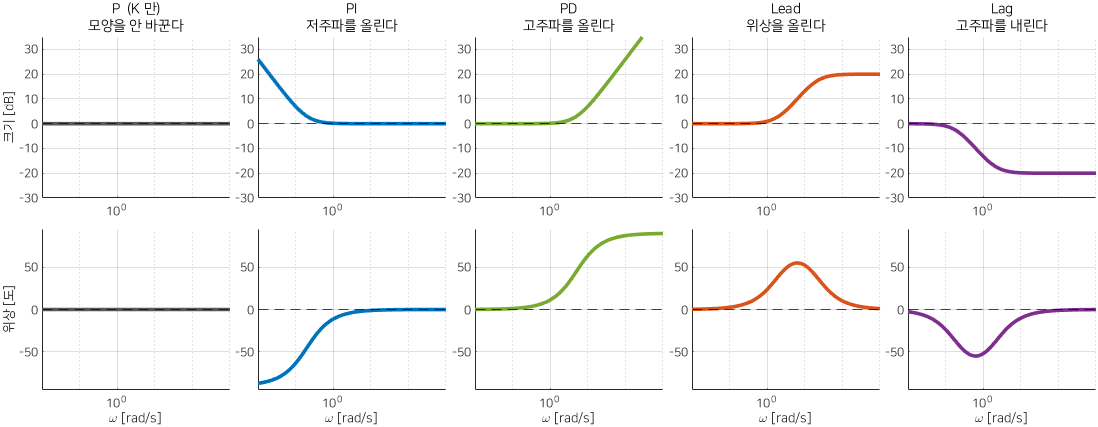

제어기 네 개의 보드 모양 — 이 네 장을 외운다

**그림 파일** `w11b_shapes.png` — `make_figures.m` 의 `fig_w11b_shapes` · 다시 만들려면 `make_figures('w11b_shapes')`

**직접 확인해 보려면** — `W11B_02_pd_lead.m` 의 **1절**과 `W11B_03_pi_lag.m` 의 **1절**이 같은 네 모양을 숫자와 함께 다시 그립니다.

그림 해석

보드 선도는 **곱이 덧셈이 되는 자리**입니다. $L = GC$ 이므로 dB 로는 $|L|_{dB} = |G|_{dB} + |C|_{dB}$ 이고 위상도 그냥 더해집니다. 그러니 설계란 플랜트 곡선에 **위 네 장 중 하나를 겹쳐 그리는 일**입니다.

오늘의 계단

- **1절** `controlSystemDesigner` — 설계를 손으로 하는 창

- **2절** 1단계는 항상 $K$ — 정상상태오차부터 맞춘다

- **3~4절** PD 와 Lead — 위상을 끌어올린다

- **5~6절** PI 와 Lag — 저주파 이득을 올린다

- **7절** 앱에서 손으로 끌어 보기

- **8절** 종합 설계 — 모터 위치제어를 끝까지

- **9절** Simulink 교차 검증 — 앱이 못 보는 두 가지

## 0-1. 가장 작은 예 — 이득만 올려 보면 어떻게 되는가

비유 — 볼륨 손잡이 하나만 있는 라디오입니다. 소리가 작으면 돌리면 됩니다. 그런데 어느 지점을 넘으면 **삐 소리가 나기 시작**합니다. 그것이 발산입니다.

손잡이가 하나뿐일 때 무슨 일이 생기는지 숫자로 봅니다. 플랜트는 오늘 내내 쓸 가장 간단한 것으로 둡니다.


$$G(s) = \frac{1}{s(s+1)}$$


극점이 $s = 0$ 과 $s = -1$ 두 개뿐이고 영점이 없습니다. 분모에 $s$ 가 하나 있으므로 **적분기가 하나 있는 플랜트**입니다 (2절에서 "형 1" 이라고 부릅니다).

G = 1/(s*(s+1));
Kv = [1 10 100]';
n0 = numel(Kv);
pm0 = zeros(n0,1); wc0 = zeros(n0,1); os0 = zeros(n0,1); ess0 = zeros(n0,1);
for k = 1:n0
    L = Kv(k)*G;
    [~, pm0(k), ~, wc0(k)] = margin(L);
    os0(k) = stepinfo(feedback(L,1)).Overshoot;
    ess0(k) = 1/Kv(k);                       % 램프 지령의 정상상태오차 (2-1절에서 유도)
end
table(Kv, ess0, pm0, wc0, os0, ...
    'VariableNames', {'K', '램프오차', 'PM_deg', 'wc', 'OS_퍼센트'})

표를 읽는 법입니다.

- $K$ 를 10배 올리면 **램프오차가 10배 줄어든다** — 좋다

- 그런데 **위상여유가 같이 줄어든다** — $51.8^\circ \to 18.0^\circ \to 5.7^\circ$

- 오버슈트는 $16\% \to 60\% \to 85\%$ 로 커진다 — 쓸 수 없다

왜 이렇게 되는가 — $K$ 는 크기 곡선을 **위로 평행이동**만 시킵니다. 위상은 전혀 건드리지 않습니다 (7-1절에서 다시 확인합니다). 그러니 곡선이 위로 올라가면 0 dB 선을 지나는 자리가 **오른쪽으로 밀려가고**, 플랜트의 위상은 오른쪽으로 갈수록 더 깎여 있으므로 위상여유가 그만큼 줄어드는 것입니다.

왜 중요한가 — 손잡이가 하나로는 부족하다는 결론입니다. **정확도를 올리면서 안정성을 지키려면 위상을 따로 올려 줄 연장이 필요합니다.** 그것이 3절의 PD 와 4절의 Lead 입니다.

## 1. `controlSystemDesigner` — 설계를 손으로 하는 창

왜 필요한가 — 위 표를 만들려고 우리는 `margin` 과 `stepinfo` 를 세 번씩 불렀습니다. 설계는 보통 이것을 **수십 번** 되풀이합니다. 영점을 조금 왼쪽으로 옮기고 다시, 극점을 오른쪽으로 옮기고 다시 — 그때마다 코드를 고쳐 돌리면 하루가 갑니다.

`controlSystemDesigner` 는 그 되풀이를 **마우스로** 하게 해 줍니다. 보드 선도 위의 꺾이는 점을 끌면 그 즉시 PM, GM, 계단응답이 전부 다시 그려집니다.

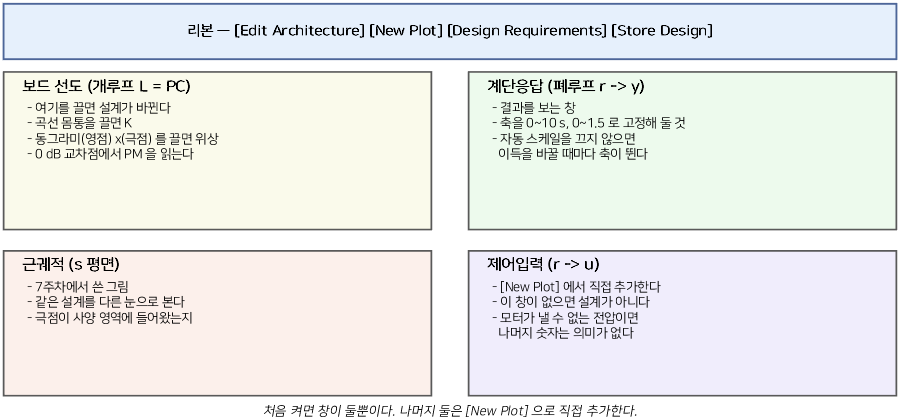

앱 화면의 구성 — 네 영역만 알면 된다

**그림 파일** `w11b_app_tour.png` — `make_figures.m` 의 `fig_w11b_app_tour` · 다시 만들려면 `make_figures('w11b_app_tour')`

그림 해석

명령 정리

- **원리** — 플랜트 $G$ 를 받아 $C$ 를 조작 대상으로 놓고, $L = GC$ 와 $T = L/(1+L)$ 을 **마우스 조작마다 다시 계산**해 그린다

- **입력** — `controlSystemDesigner(G)` 로 플랜트를 주거나, 인자 없이 불러 앱 안에서 불러온다. 근궤적으로 시작하려면 `controlSystemDesigner('rlocus', G)`

- **출력** — 화면. 설계가 끝나면 `Export` 로 $C$ 를 작업공간에 내보낸다

- **주의 1** — 앱은 **유리함수만** 다룹니다. 수송지연 $e^{-sT_d}$ 는 넣을 수 없습니다. 9절에서 Simulink 로 따로 확인해야 합니다

- **주의 2** — 앱은 **제어입력 **$u$** 를 기본 화면에 보여 주지 않습니다.** 8-6절에서 꼭 따로 재야 합니다

예제 — 아래 한 줄을 명령창에 치면 앱이 열립니다. 강의노트에서는 창을 띄우지 않고 같은 계산을 코드로 합니다.

>> G = tf(1, [1 1 0]);  controlSystemDesigner(G)

7주차에서 쓴 `controlSystemDesigner` 와 **같은 앱**입니다. 그때는 근궤적 평면에서 극점을 끌었고, 오늘은 보드 선도에서 꺾이는 점을 끕니다. 창의 왼쪽 위에서 보기를 바꾸는 것뿐입니다.

## 1-1. 처음에 해 둘 세 가지

왜 필요한가 — 앱을 켜고 바로 끌기 시작하면 그림이 계속 자동으로 스케일을 바꿔서 **무엇이 좋아지고 무엇이 나빠지는지 비교가 안 됩니다.** 끌 때마다 축이 움직이면 눈이 속습니다.

그래서 끌기 전에 세 가지를 해 둡니다. 수업 영상에서 교수가 매번 먼저 하는 것입니다.

세 번째가 가장 중요합니다. 2번만 하고 3번을 빼먹으면 다음 조작에서 축이 다시 자동으로 벌어집니다.

그리고 **사양선을 그려 놓습니다** (7-4절). 오버슈트 $20\%$ 가 사양이면 계단응답 그림에 $1.2$ 선을 그어 두는 것입니다. 그러면 끌면서 선을 넘는지 보는 것만으로 합격 여부를 압니다. 숫자를 읽을 필요가 없습니다.

## 1-2. 무엇을 편집하는가 — $C$ 를 고른다

왜 필요한가 — 앱 안에는 블록이 여러 개 있습니다 ($C$, $G$, $H$, $F$). 아무것도 고르지 않고 끌면 엉뚱한 블록이 바뀝니다.

앱의 기본 구조는 이렇습니다. 10주차와 11A주차에서 쓴 그림과 같지만 **앞먹임 블록 **$F$ 가 하나 더 있습니다.

dg_loop('controller');

그림 해석

하는 법 — 앱의 **Controllers and Fixed Blocks** 패널에서 `C` 를 클릭합니다. 그러면 아래 편집창에 $C$ 의 영점·극점·이득 목록이 나오고, 거기서 **Add Pole/Zero** 로 모양을 추가합니다. 끌기도 그때부터 $C$ 에만 먹습니다.

오늘 쓰는 추가 항목은 이 네 개뿐입니다.

적분기 하나만 더하고 싶으면 **Add real pole** 로 $s = 0$ 에 극점을 놓습니다. 그것이 5절의 PI 입니다.

## 2. 설계의 1단계는 항상 $K$ — 정상상태오차부터 맞춘다

왜 필요한가 — 설계 순서를 거꾸로 하면 일을 두 번 합니다. 위상여유를 먼저 맞춰 놓고 나중에 $K$ 를 올리면, 올린 만큼 교차주파수가 오른쪽으로 가서 **위상여유가 다시 무너집니다** (0-1절에서 본 그것입니다).

그래서 순서는 언제나 이렇습니다.

그런데 1단계를 하려면 **정상상태오차와 **$K$** 의 관계**를 알아야 합니다. 5주차에서 배운 것을 여기서 다시 꺼냅니다.

## 2-1. 시스템 형과 오차상수 — 손으로 $K_p$, $K_v$, $K_a$

비유 — 달리는 버스를 쫓아가는 사람입니다. 버스가 서 있으면(계단) 언젠가는 잡습니다. 일정한 속도로 가면(램프) 일정한 거리만큼 뒤쳐집니다. 가속하면 (포물선) 점점 멀어집니다. **지령이 빠를수록 오차가 커지는 것**이 핵심입니다.

가장 작은 예 — 루프이득이 $L = K/s$ 라고 해 봅시다. 램프 지령 $r = t$ 에 대한 오차는 최종값 정리로 구합니다.


$$e_{ss} = \lim_{s \to 0} s \cdot E(s) = \lim_{s \to 0} s \cdot \frac{1}{1+L(s)} \cdot \frac{1}{s^2}$$


유도 — 램프의 라플라스 변환이 $1/s^2$ 이고, 오차는 $E = S \cdot R = R/(1+L)$ 입니다. $L = K/s$ 를 넣으면


$$e_{ss} = \lim_{s \to 0} \frac{1}{s} \cdot \frac{1}{1 + K/s} = \lim_{s \to 0} \frac{1}{s + K} = \frac{1}{K}$$


손계산 — $K = 100$ 이면 $e_{ss} = 0.01$ 입니다. 0-1절 표의 둘째 열이 바로 이것입니다.

일반화 — 지령의 종류와 플랜트의 적분기 개수를 **표로 정리**합니다. 적분기 개수를 **시스템 형**(type) 이라고 부릅니다.

외우는 법 — **대각선으로 유한한 값이 하나씩 내려갑니다.** 형이 하나 올라가면 오차가 $0$ 이 되는 지령이 하나 늘어납니다.

보드 선도에서는 이것이 **저주파 기울기**로 보입니다.

그래서 **앱의 보드 선도 왼쪽 끝 기울기만 보면 시스템 형을 알 수 있습니다.** 이것이 설계할 때 가장 먼저 보는 것입니다.

MATLAB 검산 — 위 세 식을 `dcgain` 으로 그대로 확인합니다.

G1 = 1/(s*(s+1));                     % 형 1
G0 = 1/((s+1)*(s/5+1));               % 형 0 (5절에서 쓸 플랜트)
nm = {'형 1 : 1/(s(s+1))'; '형 0 : 1/((s+1)(s/5+1))'};
Kp_ = [dcgain(100*G1); dcgain(100*G0)];
Kv_ = [dcgain(s*100*G1); dcgain(s*100*G0)];
table(nm, Kp_, Kv_, 1./(1+Kp_), 1./Kv_, ...
    'VariableNames', {'플랜트', 'Kp', 'Kv', '계단오차', '램프오차'})

읽는 법 — 형 1 은 $K_p$ 가 무한이라 계단오차가 $0$ 이고, $K_v = 100$ 이라 램프오차가 $0.01$ 입니다. 형 0 은 $K_p = 100$ 이라 계단오차가 $1/101 = 0.0099$, $K_v = 0$ 이라 램프오차가 무한입니다.

왜 중요한가 — 사양이 "램프 오차 $0.01$ 이하" 로 주어지면 이 표만으로 $K$** 가 바로 정해집니다.** 그것이 2-2절입니다.

## 2-2. 예제 — 램프 오차 $0.01$ 을 맞추려면 $K = 100$

사양 — $G = 1/(s(s+1))$ 에 비례제어기를 걸어 **기울기 1 의 램프를 쫓을 때 정상상태오차를 **$0.01$** 이하**로 만든다.

손계산 — $L = KG = K/(s(s+1))$ 이므로


$$K_v = \lim_{s \to 0} s L(s) = \lim_{s \to 0} \frac{K}{s+1} = K$$


즉 $e_{ss} = 1/K \le 0.01$ 이려면 $K \ge 100$ 입니다. **딱 **$K = 100$** 을 씁니다.**

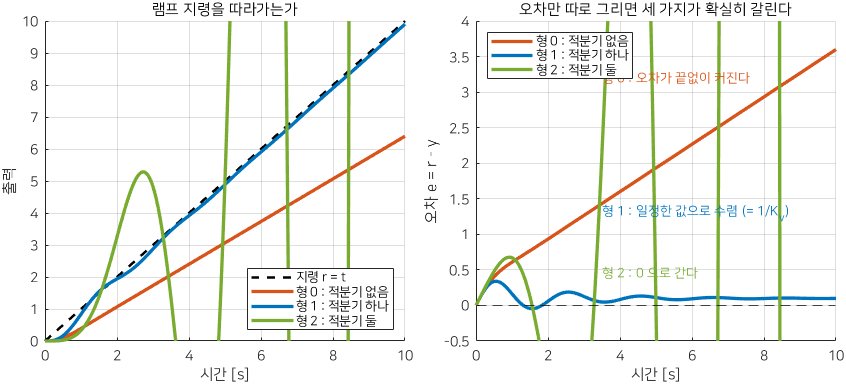

램프를 쫓는 모습과 그때의 오차

**그림 파일** `w11b_type_ramp.png` — `make_figures.m` 의 `fig_w11b_type_ramp` · 다시 만들려면 `make_figures('w11b_type_ramp')`

그림 해석

MATLAB 검산 — 교수님 수업 코드와 같은 방식으로 `lsim` 에 램프를 넣습니다.

Kpick = 100;
Lp = Kpick*G1;
Tp = feedback(Lp, 1);
tr = (0:0.01:20)';
rr = tr;                                    % 기울기 1 의 램프
yr = lsim(Tp, rr, tr);
er = rr - yr;
y10 = lsim(feedback(10*G1, 1), rr, tr);     % K=10 도 같은 방법으로 한 번 더
e10 = rr - y10;
table([10; 100], [1/10; 1/100], [e10(end); er(end)], ...
    'VariableNames', {'K', '공식_1_over_Kv', '실측_마지막오차'})

읽는 법 — 공식과 실측이 소수 넷째 자리까지 같습니다. 램프는 20 초면 충분히 정상상태에 듭니다.

그림으로도 확인합니다.

tiledlayout(2, 1, 'TileSpacing', 'compact');
nexttile; hold on; grid on;
plot(tr, rr, '--', 'LineWidth', 2);
plot(tr, yr, 'LineWidth', 2.2);
xlabel('시간 [s]'); ylabel('위치');
legend('지령 램프', 'K = 100 의 출력', 'Location', 'northwest');
title('나란히 간다 — 간격이 정상상태오차');
nexttile; hold on; grid on;
plot(tr, er, 'LineWidth', 2.2);
yline(0.01, 'r--', 'LineWidth', 1.5);
xlabel('시간 [s]'); ylabel('오차 r - y'); ylim([-0.1 0.3]);
legend('오차', '사양 0.01', 'Location', 'northeast');
title('0.01 로 수렴한다');

## 2-3. 그런데 $K$ 만으로는 끝나지 않는다

$K = 100$ 으로 사양 하나는 지켰습니다. 나머지를 재 봅니다.

L100 = 100*G1;
[gm1, pm1, ~, wc1] = margin(L100);
T100 = feedback(L100, 1);
si1 = stepinfo(T100);
table(pm1, 20*log10(gm1), wc1, si1.Overshoot, si1.SettlingTime, bandwidth(T100), ...
    'VariableNames', {'PM_deg', 'GM_dB', 'wc', 'OS_퍼센트', 'ts', 'wb'})

읽는 법 — 위상여유가 $5.7^\circ$ 입니다. 11A주차 3-4절의 어림셈 $\zeta \approx PM/100$ 으로 보면 감쇠비가 $0.057$ 입니다. 거의 감쇠가 없습니다. 오버슈트 $85\%$ 는 실물에서는 쓸 수 없는 값입니다.

왜 이렇게 되었는가 — 보드 선도로 보면 분명합니다. $G$ 의 위상은 $\omega$ 가 커지면 $-90^\circ$ 에서 $-180^\circ$ 로 내려갑니다. 그런데 $K$ 를 100 으로 올려 교차주파수를 $\omega_c = 9.98$ 까지 밀어 놓았습니다. 그 자리에서 $G$ 의 위상은 이미 $-174.3^\circ$ 입니다.

w_check = [1 5 10 20]';
table(w_check, squeeze(angle(freqresp(G1, w_check)))*180/pi, ...
    180 + squeeze(angle(freqresp(G1, w_check)))*180/pi, ...
    'VariableNames', {'w_rad_s', 'G_위상_deg', '그자리의_PM_deg'})

읽는 법 — 마지막 열이 **"교차주파수가 여기라면 PM 이 얼마겠는가"** 입니다. $\omega = 10$ 에서는 $5.7^\circ$ 밖에 안 됩니다.

여기서 **두 가지 길**이 있습니다.

(가) 가 이 예제의 답입니다. 사양이 $K_v \ge 100$ 을 요구하므로 $K$ 를 내릴 수 없고, 그렇다면 그 자리에서 위상을 끌어올리는 수밖에 없습니다.

## 3. PD — 위상을 끌어올린다

비유 — 7주차의 그 비유입니다. 운전할 때 **앞을 보고 미리 핸들을 돌리는 것** 입니다. 지금의 오차만 보지 않고 오차가 **어느 쪽으로 변하고 있는지**를 봅니다.

가장 작은 예 — 제어기를 이렇게 둡니다.


$$C(s) = K(1 + T_d s)$$


기호의 뜻

왜 이것이 위상을 올리는가 — $s = j\omega$ 를 넣어 봅니다.


$$C(j\omega) = K(1 + j\omega T_d)$$


이것은 실수부가 $K$, 허수부가 $K\omega T_d$ 인 복소수입니다. 허수부가 **항상 양수**이므로 위상이 항상 $+$ 입니다.


$$\angle C(j\omega) = \arctan(\omega T_d)$$


손계산 — $T_d = 0.1$ 이라고 두면

- $\omega = 1$ : $\arctan(0.1) = 5.7^\circ$ — 거의 안 올라간다

- $\omega = 10 = 1/T_d$ : $\arctan(1) = 45^\circ$ — **꺾이는 자리에서 정확히 절반**

- $\omega = 100$ : $\arctan(10) = 84.3^\circ$ — 거의 $90^\circ$

크기는 이렇습니다.


$$|C(j\omega)| = K\sqrt{1 + (\omega T_d)^2}$$


- $\omega \ll 1/T_d$ : $|C| \approx K$ — 평평하다

- $\omega \gg 1/T_d$ : $|C| \approx K \omega T_d$ — $+20$ dB/dec 로 **끝없이 올라간다**

MATLAB 검산 — 세 주파수에서 공식과 `freqresp` 를 맞대 봅니다.

Td = 0.1;
Cpd = 1 + Td*s;
wpd = [1; 10; 100];
table(wpd, atand(wpd*Td), squeeze(angle(freqresp(Cpd, wpd)))*180/pi, ...
    20*log10(sqrt(1 + (wpd*Td).^2)), 20*log10(squeeze(abs(freqresp(Cpd, wpd)))), ...
    'VariableNames', {'w_rad_s', '위상_공식', '위상_실측', '크기_공식_dB', '크기_실측_dB'})

읽는 법 — 공식과 실측이 완전히 같습니다. 꺾이는 자리 $\omega = 1/T_d = 10$ 에서 위상이 정확히 $45^\circ$, 크기가 $3.01$ dB 인 것을 확인하십시오. $3$** dB 와 **$45^\circ$** 는 꺾이는 자리의 표시**입니다 (9주차에서 배운 그것).

왜 중요한가 — 위상을 올리고 싶은 주파수가 $\omega_c$ 라면, $1/T_d$ 를 그 근처나 그보다 **왼쪽**에 놓으면 됩니다. 그러면 $\omega_c$ 에서 이미 위상이 충분히 올라와 있습니다.

## 3-1. 앱에서 PD 는 "Add real zero" 다

앱의 메뉴 이름이 PD 가 아닙니다. 왜 같은 것인지 확인합니다.


$$C(s) = K(1 + T_d s) = K T_d \left( s + \frac{1}{T_d} \right)$$


즉 $s = -1/T_d$** 에 실영점 하나를 더하고 이득을 **$K T_d$** 로 바꾼 것**과 완전히 같습니다. 그래서 앱 메뉴가 **Add real zero** 입니다.

그래서 앱에서 PD 설계는 두 동작뿐입니다 — **동그라미를 하나 놓고 왼쪽으로 끈다.**

## 3-2. 예제 — $T_d$ 를 바꿔 본다

2-3절에서 막힌 자리로 돌아갑니다. $G = 1/(s(s+1))$, $K = 100$ 고정, $T_d$ 만 바꿉니다. 교수님 수업의 Example 7-1 과 같은 설정입니다.

Tdv = [0.05; 0.1; 0.2; 1];
n1 = numel(Tdv);
pm_pd = zeros(n1,1); wc_pd = zeros(n1,1); os_pd = zeros(n1,1);
ts_pd = zeros(n1,1); hf_pd = zeros(n1,1);
for k = 1:n1
    Ck = 100*(1 + Tdv(k)*s);
    Lk = Ck*G1;
    [~, pm_pd(k), ~, wc_pd(k)] = margin(Lk);
    sk = stepinfo(feedback(Lk,1));
    os_pd(k) = sk.Overshoot;  ts_pd(k) = sk.SettlingTime;
    hf_pd(k) = 20*log10(abs(evalfr(Ck, 1000i)));    % w=1000 에서의 제어기 크기
end
table(Tdv, 1./Tdv, pm_pd, wc_pd, os_pd, ts_pd, hf_pd, ...
    'VariableNames', {'Td', '꺾이는자리', 'PM_deg', 'wc', 'OS_퍼센트', 'ts', 'C크기_w1000_dB'})

읽는 법 — 세 가지를 보십시오.

- $T_d$** 를 키우면 PM 이 올라간다** : $33^\circ \to 56^\circ \to 79^\circ \to 90^\circ$

- **정착시간이 극적으로 줄어든다** : $K$ 만 쓸 때 $7.6$ 초였던 것이 $0.5$ 초까지

- **그런데 마지막 열이 같이 커진다** : $66$ dB $\to$ $100$ dB. $\omega = 1000$ 에서 제어기 이득이 10만 배라는 뜻입니다

마지막 줄 $T_d = 1$ 은 PM $90^\circ$, 오버슈트 $0\%$ 로 **완벽해 보입니다.** 그런데 교차주파수가 $100$ rad/s 이고 $\omega = 1000$ 에서 제어기 이득이 $100$ dB 입니다. 이것이 3-3절의 문제입니다.

비교 그림을 그립니다.

tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile; hold on; grid on;
tt = (0:0.002:3)';
plot(tt, step(feedback(100*G1,1), tt), '--', 'LineWidth', 2);
for k = [2 3]
    plot(tt, step(feedback(100*(1+Tdv(k)*s)*G1,1), tt), 'LineWidth', 2.2);
end
yline(1, 'k:');
xlabel('시간 [s]'); ylabel('출력'); ylim([0 2]);
legend('K 만 (Td=0)', 'Td = 0.1', 'Td = 0.2', 'Location', 'southeast');
title('PD 를 넣으면 흔들림이 사라진다');
nexttile; hold on; grid on;
wb = logspace(-1, 3, 400);
for k = [1 2 4]
    semilogx(wb, 20*log10(squeeze(abs(freqresp(100*(1+Tdv(k)*s), wb)))), ...
        'LineWidth', 2.2, 'DisplayName', sprintf('Td = %g', Tdv(k)));
end
set(gca, 'XScale', 'log');
xlabel('주파수 [rad/s]'); ylabel('|C| [dB]');
legend('Location', 'northwest');
title('그 대가 — 고주파가 끝없이 올라간다');

## 3-3. PD 의 대가 — 고주파가 끝없이 올라간다

왜 문제인가 — 세 가지가 동시에 일어납니다.

둘째 문제를 숫자로 확인합니다. 그런데 **진짜 계단으로는 계산 자체가 안 됩니다.** 이유를 먼저 보겠습니다. 지령에서 제어입력까지의 전달함수는


$$\frac{u}{r} = \frac{C}{1 + CG}$$


이고 $s \to \infty$ 를 넣어 보면


$$C(s) = K(1 + T_d s) \to \infty, \qquad C(s)G(s) = \frac{K(1+T_d s)}{s(s+1)} \to 0$$


이므로 $u/r \to C \to \infty$ 입니다. 분자 차수가 분모보다 높은 것(비적정, improper)이고, `lsim` 은 이런 시스템을 아예 거부합니다. **수학이 "계단은 무리입니다" 라고 말해 주는 것입니다.**

그러니 현실처럼 지령을 조금 부드럽게 만들어 넣습니다. 시간상수 $\tau = 0.05$ 초의 1차 필터를 통과시킨 계단입니다 — 0.05 초 만에 올라가는, 충분히 급한 지령입니다.

tau = 0.05;
Rsmooth = tf(1, [tau 1]);                  % 부드럽게 올라가는 지령
tt2 = (0:1e-4:1)';
umax_pd = zeros(n1, 1);
for k = 1:n1
    Ck = 100*(1 + Tdv(k)*s);
    Gu = minreal(Ck/(1 + Ck*G1));          % r -> u
    uu = lsim(minreal(Gu*Rsmooth), ones(size(tt2)), tt2);
    umax_pd(k) = max(abs(uu));
end
table(Tdv, 100*Tdv/tau, umax_pd, ...
    'VariableNames', {'Td', '공식_K_Td_over_tau', 'umax_실측'})

읽는 법 — 둘째 열과 셋째 열이 **정확히 같습니다**. 제어기의 미분항이 지령의 기울기를 그대로 받기 때문입니다. 지령이 $\tau$ 초 만에 $1$ 만큼 올라가면 기울기가 $1/\tau$ 이고, $C$ 의 미분항이 그것에 $K T_d$ 를 곱합니다.


$$u_{max} = \frac{K T_d}{\tau}$$


그리고 이 식이 곧 "계단은 안 된다" 는 말입니다. 진짜 계단은 $\tau \to 0$ 이고 그러면 $u_{max} \to \infty$ 입니다. 지령을 두 배 급하게 만들면 필요한 전압이 두 배가 됩니다.

**PD 는 순수한 형태로는 쓸 수 없습니다.** $T_d = 1$ 은 PM $90^\circ$ 를 주지만 제어입력이 $2000$ 이 필요합니다. 모터가 $12$ V 짜리면 그냥 포화됩니다. 가장 작은 $T_d = 0.05$ 조차 $100$ 이 필요합니다.

왜 중요한가 — 그래서 **고주파에서 멈추는 PD** 가 필요합니다. 그것이 Lead 입니다.

## 4. Lead — PD 의 현실판

왜 필요한가 — PD 의 크기가 끝없이 올라가는 것은 분모가 $1$ 이기 때문입니다. **분모에 극점을 하나 넣어 어느 주파수부터 다시 평평해지게** 만들면 됩니다.


$$C(s) = K \frac{1 + Ts}{1 + \alpha T s}, \qquad 0 < \alpha < 1$$


기호의 뜻

$\alpha < 1$ 이므로 $1/(\alpha T) > 1/T$ 입니다. 즉 **영점이 극점보다 왼쪽**입니다. 이것이 Lead 의 정의입니다. 반대로 놓으면 Lag 가 됩니다 (6절, 7-3절).

가장 작은 예 — $\alpha = 0.1$, $T = 1$ 로 두면 영점이 $1$, 극점이 $10$ 입니다. 저주파 이득은 $K$, 고주파 이득은 $K/\alpha = 10K$ 입니다. 그 사이 한 데케이드 동안 $20$ dB 올라가고 **거기서 멈춥니다.**

Clead0 = (1 + s)/(1 + 0.1*s);
wl = [0.01; 1; 3.162; 10; 1000];
table(wl, 20*log10(squeeze(abs(freqresp(Clead0, wl)))), ...
    squeeze(angle(freqresp(Clead0, wl)))*180/pi, ...
    'VariableNames', {'w_rad_s', '크기_dB', '위상_deg'})

읽는 법 — $\omega = 0.01$ 에서 $0$ dB, $\omega = 1000$ 에서 $20$ dB 로 **멈춰 있습니다.** 그리고 위상이 가장 높은 곳은 $\omega = 3.162$ 입니다. 이 값은 $\sqrt{1 \times 10} = 3.162$, 즉 **두 꺾이는 자리의 기하평균**입니다. 다음 절에서 이것을 유도합니다.

## 4-1. 최대 위상과 $\alpha$ — 유도

왜 필요한가 — 설계할 때 우리가 원하는 것은 "이 주파수에서 위상을 $50^\circ$ 올려 달라" 입니다. 그러려면 $\alpha$ 와 $T$ 를 그 요구에서 거꾸로 계산해야 합니다.

**1단계 위상 식을 쓴다.**


$$\angle C(j\omega) = \arctan(\omega T) - \arctan(\alpha \omega T)$$


영점이 $+\arctan$, 극점이 $-\arctan$ 을 줍니다. $\alpha < 1$ 이므로 앞의 항이 항상 크고, 따라서 **위상이 항상 **$+$ 입니다.

**2단계 최대가 되는 곳을 찾는다.** tan 의 덧셈정리를 씁니다. $x = \omega T$ 로 두면


$$\tan \phi = \frac{x - \alpha x}{1 + \alpha x^2} = \frac{(1-\alpha)x}{1 + \alpha x^2}$$


이것을 $x$ 로 미분해 $0$ 으로 둡니다. 분자의 미분이 $0$ 이면 되므로


$$(1-\alpha)(1 + \alpha x^2) - (1-\alpha)x \cdot 2\alpha x = 0$$


$(1-\alpha)$ 로 나누면 $1 + \alpha x^2 - 2\alpha x^2 = 0$, 즉 $1 = \alpha x^2$ 입니다. 따라서


$$x = \omega T = \frac{1}{\sqrt{\alpha}} \quad \Rightarrow \quad \omega_{max} = \frac{1}{T\sqrt{\alpha}} = \sqrt{\frac{1}{T} \cdot \frac{1}{\alpha T}}$$


**두 꺾이는 자리의 기하평균**입니다. 로그축에서는 정확히 **가운데**입니다.

**3단계 그 자리의 위상을 구한다.** $x = 1/\sqrt{\alpha}$ 를 넣습니다.


$$\tan \phi_{max} = \frac{(1-\alpha)/\sqrt{\alpha}}{1 + \alpha \cdot (1/\alpha)} = \frac{1-\alpha}{2\sqrt{\alpha}}$$


$\tan$ 을 $\sin$ 으로 바꾸면 ($1 + \tan^2$ 을 쓰면 분모가 $\frac{1+\alpha}{2\sqrt{\alpha}}$ 가 됩니다)


$$\sin \phi_{max} = \frac{1-\alpha}{1+\alpha} \quad \Rightarrow \quad \alpha = \frac{1 - \sin\phi_{max}}{1 + \sin\phi_{max}}$$


**4단계 그 자리의 크기도 구한다.** 같은 $x$ 를 크기식에 넣으면


$$|C(j\omega_{max})| = K \frac{\sqrt{1 + 1/\alpha}}{\sqrt{1 + \alpha}} = \frac{K}{\sqrt{\alpha}}$$


dB 로는 $20\log_{10}(K) - 10\log_{10}(\alpha)$ 입니다. 즉 $\omega_{max}$** 에서 크기가 **$-10\log_{10}\alpha$** dB 만큼 올라가 있습니다.** 이것이 설계에서 중요한 이유는 7절에서 봅니다 — 크기가 올라가면 교차주파수가 오른쪽으로 밀립니다.

손계산 — $\phi_{max} = 50^\circ$ 를 넣어 봅니다. $\sin 50^\circ = 0.766$ 이므로


$$\alpha = \frac{1 - 0.766}{1 + 0.766} = \frac{0.234}{1.766} = 0.1325$$


그리고 $-10\log_{10}(0.1325) = 8.78$ dB 입니다.

MATLAB 검산 — 네 각도에 대해 공식과 실측을 맞대 봅니다.

phiv = [20; 35; 50; 65];
n2 = numel(phiv);
alv = (1 - sind(phiv))./(1 + sind(phiv));
ph_meas = zeros(n2,1); mg_meas = zeros(n2,1); wmax_meas = zeros(n2,1);
wsc = logspace(-2, 2, 20001);
for k = 1:n2
    Ck = (1 + s)/(1 + alv(k)*s);            % T = 1 로 두면 wmax = 1/sqrt(alpha)
    fr = squeeze(freqresp(Ck, wsc));
    [ph_meas(k), i_] = max(angle(fr)*180/pi);
    wmax_meas(k) = wsc(i_);
    mg_meas(k) = 20*log10(abs(fr(i_)));
end
table(phiv, alv, ph_meas, 1./sqrt(alv), wmax_meas, -10*log10(alv), mg_meas, ...
    'VariableNames', {'phi_목표', 'alpha', 'phi_실측', 'wmax_공식', 'wmax_실측', ...
                      '크기_공식_dB', '크기_실측_dB'})

읽는 법 — 네 줄 모두 공식과 실측이 일치합니다. 그리고 표에서 **중요한 경고**가 하나 읽힙니다.

- $\phi_{max} = 65^\circ$ 는 $\alpha = 0.0545$ 입니다. 고주파 이득이 $18$ 배입니다

- $\phi_{max} = 70^\circ$ 를 넣으면 $\alpha = 0.0311$, $32$ 배가 됩니다

- $\phi_{max} \to 90^\circ$ 면 $\alpha \to 0$, 즉 **PD 로 되돌아갑니다**

그래서 실무 규칙은 이렇습니다 — **한 단으로 **$55^\circ$** 를 넘기지 않는다.** 더 필요하면 두 단으로 나눕니다 (4-5절).

## 4-2. Lead 설계 다섯 단계

지금까지의 식을 **절차**로 정리합니다. 손으로 할 때도, 앱으로 할 때도 같습니다.

3단계에 $\epsilon$** 을 더하는 이유**가 중요합니다. Lead 를 넣으면 크기가 $-10\log_{10}\alpha$ dB 올라가므로 **교차주파수가 오른쪽으로 밀립니다.** 밀려간 자리에서는 플랜트의 위상이 더 깎여 있으니, 계산한 것보다 PM 이 덜 나옵니다. 그 손실을 미리 보태 두는 것입니다.

$\omega_{max}$ 는 어디에 놓는가 — **새 교차주파수가 될 자리**에 놓습니다. 실무 절차는 이렇습니다.

- $|KG(j\omega)| = 10\log_{10}\alpha$ dB (즉 Lead 가 올릴 양만큼 **아래**) 인 주파수를 찾아 거기를 $\omega_{max}$ 로 둔다

- 또는 그냥 현재 $\omega_c$ 의 $1.5 \sim 2$ 배에 놓고 5단계에서 조정한다

수업에서는 두 번째, **놓고 재고 고치는** 방법을 씁니다. 앱이 있으면 그것이 훨씬 빠릅니다.

## 4-3. 예제 — $\phi_{max} = 50^\circ$ 로 설계한다

2-3절에서 막힌 자리입니다. $G = 1/(s(s+1))$, $K = 100$, 현재 PM $5.7^\circ$. 목표는 **PM **$50^\circ$** 정도**로 둡니다 (오버슈트 $20\%$ 쯤).

3단계 — 필요한 위상은 $50 - 5.7 = 44.3^\circ$ 입니다. 여유를 보태 $\phi_{max} = 50^\circ$ 로 둡니다.

4단계 — 손계산입니다.


$$\alpha = \frac{1 - \sin 50^\circ}{1 + \sin 50^\circ} = 0.1325, \qquad -10\log_{10}\alpha = 8.78 \text{ dB}$$


$\omega_{max}$ 는 $|100 G(j\omega)| = -8.78$ dB 인 자리로 잡습니다. 수업 코드에서는 그 값이 $\omega_{max} = 16.7$ rad/s 로 나왔습니다. 확인합니다.

phi_max = 50;
alpha_l = (1 - sind(phi_max))/(1 + sind(phi_max));
boost = -10*log10(alpha_l);
wgrid = logspace(0, 2, 4001);
magKG = 20*log10(squeeze(abs(freqresp(100*G1, wgrid))));
[~, iw] = min(abs(magKG + boost));          % |KG| = -boost 인 자리
table(alpha_l, boost, wgrid(iw), ...
    'VariableNames', {'alpha', '올라가는_dB', 'wmax_찾은값'})

읽는 법 — $\omega_{max} = 16.56$ rad/s 가 나옵니다. 수업 코드의 $16.7$ 과 같은 자리입니다. 이 정도 차이는 설계에서 아무 의미가 없으므로 아래에서는 수업 코드의 $16.7$ 을 그대로 씁니다. 여기에 $8.78$ dB 를 보태면 그 자리가 정확히 $0$ dB, 즉 **새 교차주파수**가 됩니다. 그리고 그 자리에서 Lead 가 위상을 $50^\circ$ 올려 줍니다.

이제 $T$ 를 구해 제어기를 만듭니다.


$$T = \frac{1}{\omega_{max}\sqrt{\alpha}} = \frac{1}{16.7 \times 0.364} = 0.1645$$


w_max = 16.7;
T_l = 1/(w_max*sqrt(alpha_l));
C_lead = 100*(T_l*s + 1)/(alpha_l*T_l*s + 1);
[gm_l, pm_l, ~, wc_l] = margin(C_lead*G1);
Tl = feedback(C_lead*G1, 1);
sl = stepinfo(Tl);
table(T_l, 1/T_l, 1/(alpha_l*T_l), pm_l, 20*log10(gm_l), wc_l, sl.Overshoot, sl.SettlingTime, ...
    'VariableNames', {'T', '영점', '극점', 'PM_deg', 'GM_dB', 'wc', 'OS_퍼센트', 'ts'})

읽는 법 — PM 이 $53.5^\circ$ 로 올라갔습니다. 목표 $50^\circ$ 를 넘겼으니 5단계 합격입니다. 정착시간은 $7.6$ 초에서 $0.44$ 초로 줄었습니다.

오버슈트가 $22.5\%$ 인 것에 주의하십시오. 11A주차 3-4절의 어림셈으로는 $\zeta \approx 0.535$ 이고 그 오버슈트는 $13.3\%$ 입니다. **실측이 더 큽니다.** 이유는 11A주차 3-4절의 "(나) 폐루프 영점" 과 같습니다 — Lead 가 넣은 영점 $s = -6.08$ 이 폐루프에 그대로 남아 있습니다.

PD 와 Lead 를 나란히 놓고 봅니다.

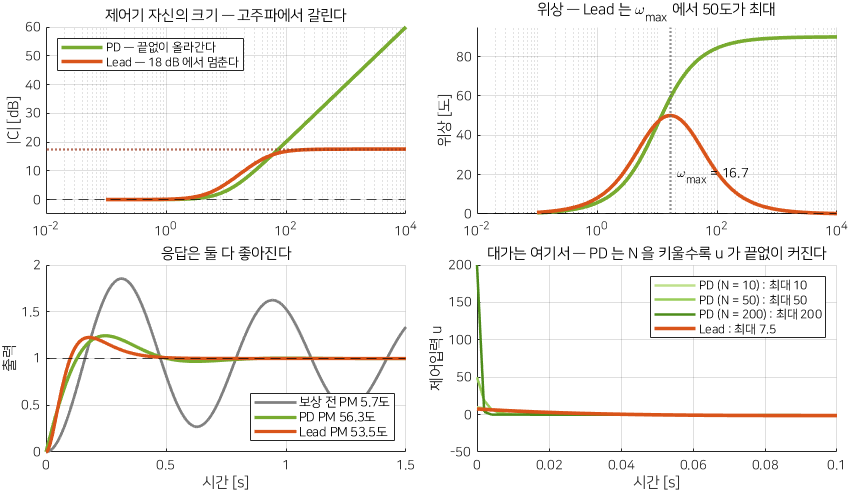

PD 와 Lead — 위상은 비슷하게 주고 고주파에서 갈린다

**그림 파일** `w11b_pd_vs_lead.png` — `make_figures.m` 의 `fig_w11b_pd_vs_lead` · 다시 만들려면 `make_figures('w11b_pd_vs_lead')`

그림 해석

왜 중요한가 — **Lead 는 필요한 곳에만 위상을 주고 빠집니다.** 그래서 실물에 쓸 수 있습니다. PD 는 안 됩니다.

## 4-4. 앱의 숫자와 손의 숫자가 같은 것임을 확인한다

왜 필요한가 — 앱에서 설계하고 Export 하면 손으로 쓴 꼴과 **다르게 생긴 식**이 나옵니다. 처음 보면 설계가 틀린 줄 알고 당황합니다.

손으로 쓴 꼴 ($\alpha$, $T$ 꼴) 과 앱이 보여 주는 꼴 (영점·극점 꼴) 을 서로 바꾸는 식입니다.


$$C(s) = K \frac{1 + Ts}{1 + \alpha T s} = K \frac{T\left(s + \frac{1}{T}\right)}{\alpha T \left(s + \frac{1}{\alpha T}\right)} = \frac{K}{\alpha} \cdot \frac{s + 1/T}{s + 1/(\alpha T)}$$


유도 — 분자와 분모에서 $s$ 의 계수를 각각 묶어냈을 뿐입니다. 묶어낸 $T$ 와 $\alpha T$ 가 약분되어 $1/\alpha$ 만 남습니다.

그래서 세 숫자의 대응은 이렇습니다.

손계산 — 4-3절의 설계를 바꿔 봅니다. $K = 100$, $\alpha = 0.1325$, $T = 0.1645$ 이므로

- 이득 : $100/0.1325 = 754.9$

- 영점 : $1/0.1645 = 6.078$

- 극점 : $1/(0.1325 \times 0.1645) = 45.88$

즉 $C = 754.86 \frac{s + 6.078}{s + 45.88}$ 입니다. 수업 코드의 `D2` 가 바로 이 숫자입니다. 두 꼴이 같은 제어기인지 MATLAB 으로 확인합니다.

D_hand = 100*(T_l*s + 1)/(alpha_l*T_l*s + 1);        % 손으로 쓴 꼴
D_app  = 754.86*(s + 6.078)/(s + 45.88);             % 앱이 보여 주는 꼴
w_cmp = [0.1; 1; 16.7; 100; 1000];
table(w_cmp, 20*log10(squeeze(abs(freqresp(D_hand, w_cmp)))), ...
    20*log10(squeeze(abs(freqresp(D_app, w_cmp)))), ...
    squeeze(angle(freqresp(D_hand, w_cmp)))*180/pi, ...
    squeeze(angle(freqresp(D_app, w_cmp)))*180/pi, ...
    'VariableNames', {'w_rad_s', '손_크기_dB', '앱_크기_dB', '손_위상', '앱_위상'})

읽는 법 — 다섯 주파수에서 소수 둘째 자리까지 같습니다. **같은 제어기입니다.** 앱에서 `Edit Compensator` 창의 아래쪽에 있는 표시 형식 선택에서 **Time constant** 와 **Zero/pole/gain** 을 서로 바꿔 볼 수 있습니다.

왜 중요한가 — 시험에서 "앱으로 설계한 결과를 손계산과 비교하라" 는 문제가 나오면 이 변환식이 답입니다. 그리고 실무에서는 **앱 결과를 코드로 옮길 때** 반드시 이 확인을 합니다.

## 4-5. 한 단으로 안 되면 두 단

왜 필요한가 — 4-1절에서 한 단 Lead 가 줄 수 있는 위상에 한계가 있다고 했습니다. 실제로 막히는 예를 봅니다. 교수님 수업의 Example 7-3 입니다.


$$G(s) = \frac{10}{s(s+1)(s/5+1)}$$


극점이 $0$, $-1$, $-5$ 세 개입니다. 적분기 하나에 극점 두 개가 더 있으니 위상이 $-270^\circ$ 까지 내려갑니다.

Gc = 10/(s*(s+1)*(s/5+1));
[gm_c, pm_c, wg_c, wc_c] = margin(Gc);
table(pm_c, 20*log10(gm_c), wc_c, wg_c, ...
    'VariableNames', {'PM_deg', 'GM_dB', 'wc', 'w_at_180deg'})

읽는 법 — **PM 이 음수**이고 GM 도 음수입니다. 이 루프는 닫으면 발산합니다. 위상여유를 $0$ 에서 $40^\circ$ 까지 올려야 하니 $50^\circ$** 이상**이 필요합니다.

1단 Lead 를 넣어 봅니다. 수업 코드의 값 $T = 0.67$, $\alpha = 0.1$ 입니다.

C1s = (0.67*s + 1)/(0.067*s + 1);
C2s = C1s*(0.27*s + 1)/(0.3*0.27*s + 1);
nmc = {'맨몸'; '1단 Lead'; '2단 Lead'};
Lc = {Gc, C1s*Gc, C2s*Gc};
pmc = zeros(3,1); gmc = zeros(3,1); wcc = zeros(3,1); osc = zeros(3,1);
for k = 1:3
    [g_, p_, ~, w_] = margin(Lc{k});
    pmc(k) = p_; gmc(k) = 20*log10(g_); wcc(k) = w_;
    if p_ > 0, osc(k) = stepinfo(feedback(Lc{k},1)).Overshoot; else, osc(k) = NaN; end
end
table(nmc, pmc, gmc, wcc, osc, ...
    'VariableNames', {'제어기', 'PM_deg', 'GM_dB', 'wc', 'OS_퍼센트'})

읽는 법 — 이것이 오늘 가장 중요한 표입니다.

- **1단으로는 PM **$23.3^\circ$** 까지밖에 못 온다.** 안정은 되었지만 사양 미달

- **2단을 넣으면 **$40.9^\circ$**.** 합격

- 교차주파수도 $2.86 \to 4.75 \to 6.72$ 로 계속 오른쪽으로 밀린다

왜 1단으로 안 되는가 — Lead 를 넣으면 크기가 올라가 $\omega_c$ 가 오른쪽으로 갑니다. 이 플랜트는 오른쪽으로 갈수록 위상이 **빠르게** 떨어지므로 (극점이 세 개라서) Lead 가 올려 준 위상을 플랜트가 바로 되먹습니다. **쫓아가기 경쟁**이 되는 것입니다.

두 단의 설계값은 어떻게 고르는가 — 한 단씩 **다른 주파수에** 놓습니다.

nm2 = {'1단'; '2단'};
Ts2 = [0.67; 0.27]; al2 = [0.1; 0.3];
table(nm2, Ts2, al2, 1./Ts2, 1./(al2.*Ts2), asind((1-al2)./(1+al2)), -10*log10(al2), ...
    'VariableNames', {'단', 'T', 'alpha', '영점', '극점', 'phi_max_deg', '올리는_dB'})

읽는 법 — 1단은 $\omega_{max} = 1/(T\sqrt\alpha) = 4.72$ 에서 $54.9^\circ$ 를, 2단은 $\omega_{max} = 6.76$ 에서 $32.6^\circ$ 를 줍니다. 두 봉우리를 **조금 떨어뜨려 놓아** 넓은 주파수대에서 위상을 받쳐 주는 것입니다.

앱에서는 **Add lead** 를 두 번 누르면 됩니다. 그러면 영점 두 개, 극점 두 개가 생기고 각각 따로 끌 수 있습니다.

왜 중요한가 — 8절의 종합 설계에서 똑같은 상황이 나옵니다. 그때는 **두 단을 쓰는 것이 유일한 답**입니다.

## 5. PI — 정상상태오차를 $0$ 으로

왜 필요한가 — 지금까지는 플랜트에 적분기가 있어서 ($G = 1/(s(s+1))$) 계단오차가 알아서 $0$ 이었습니다. 적분기가 없으면 어떻게 되는지 봅니다.

이제 플랜트를 바꿉니다. 교수님 수업 Example 7-4 의 플랜트입니다.


$$G(s) = \frac{1}{(s+1)(s/5+1)}$$


극점이 $-1$ 과 $-5$ 두 개이고 **적분기가 없습니다.** 형 0 입니다.

G2 = 1/((s+1)*(s/5+1));
Kv2 = [1; 10; 100];
n3 = numel(Kv2);
ess2 = zeros(n3,1); pm2 = zeros(n3,1); wc2 = zeros(n3,1); os2 = zeros(n3,1);
for k = 1:n3
    L = Kv2(k)*G2;
    ess2(k) = 1/(1 + dcgain(L));
    T = feedback(L,1);
    [~, p_, ~, w_] = margin(L);
    pm2(k) = p_; wc2(k) = w_; os2(k) = stepinfo(T).Overshoot;
end
table(Kv2, dcgain(G2)*Kv2, ess2, 100*ess2, pm2, wc2, os2, ...
    'VariableNames', {'K', 'Kp', '계단오차', '오차_퍼센트', 'PM_deg', 'wc', 'OS_퍼센트'})

읽는 법 — 맞바꿈이 아주 선명합니다.

- $K = 10$ : 위상여유 $48^\circ$ 로 **좋지만** 오차가 $9.1\%$ 남는다

- $K = 100$ : 오차가 $0.99\%$ 로 **좋지만** 위상여유가 $15.4^\circ$ 다

$K = 1$ 줄의 PM 이 $-180^\circ$ 로 나온 것은 **계산이 틀린 것이 아닙니다.** $|L(0)| = 1$ 이라 $0$ dB 선에 딱 접하는 특이한 경우여서 `margin` 이 교차점을 못 찾은 것입니다. $K = 1$ 은 이 플랜트에서 쓰지 않습니다.

어느 쪽도 쓸 수 없습니다. **오차를 **$0$** 으로 만드는 다른 길**이 필요합니다.

비유 — 저울의 영점 조절 나사입니다. 아무리 조심해서 재도 조금씩 어긋나면, 어긋난 양을 **계속 쌓아서** 그만큼 미리 보정해 주는 것입니다. 적분이 하는 일이 바로 그것입니다.

## 5-1. PI 의 보드 모양 — 유도

제어기를 이렇게 둡니다. 교수님 수업의 표기입니다.


$$C(s) = K \left( 1 + \frac{1}{T_i s} \right) = K \frac{T_i s + 1}{T_i s}$$


기호의 뜻

**왜 저주파가 올라가는가** — $s \to 0$ 에서


$$C(s) = K \frac{T_i s + 1}{T_i s} \to K \cdot \frac{1}{T_i s} \to \infty$$


분모의 $s$ 때문입니다. 즉 **PI 는 루프에 적분기를 하나 더 넣는 것**이고, 따라서 2-1절의 표에서 **시스템 형을 하나 올립니다.** 형 0 이 형 1 이 되므로 계단오차가 $0$ 이 됩니다.

**고주파에서는 어떤가** — $s \to \infty$ 에서


$$C(s) = K \frac{T_i s + 1}{T_i s} \to K \frac{T_i s}{T_i s} = K$$


즉 **고주파 이득은 그냥 **$K$ 입니다. PD 와 정반대입니다. PD 는 고주파가 터지고 PI 는 **저주파가 터집니다.**

위상은 이렇습니다.


$$\angle C(j\omega) = \arctan(\omega T_i) - 90^\circ$$


분모의 $j\omega$ 가 $-90^\circ$ 를 주고 분자의 영점이 $+\arctan$ 을 줍니다. 그래서 위상이 **항상 음수**입니다. 즉 PI 는 **위상여유를 깎습니다.**

손계산 — $K = 10$, $T_i = 1/0.6 = 1.667$ 이라고 둡니다. 꺾이는 자리는 $1/T_i = 0.6$ rad/s 입니다. $\omega = 6$ (꺾이는 자리의 10배) 에서


$$\angle C = \arctan(6 \times 1.667) - 90^\circ = \arctan(10) - 90^\circ = 84.3^\circ - 90^\circ = -5.7^\circ$$


즉 꺾이는 자리에서 **한 데케이드 오른쪽으로 가면 위상 손실이 **$5.7^\circ$** 뿐**입니다. 그래서 실무 규칙이 나옵니다.

$1/T_i$** 를 교차주파수의 **$1/10$** 쯤에 놓는다.**

그러면 저주파 이득은 무한으로 올리면서 교차주파수의 위상은 거의 안 건드립니다.

MATLAB 검산 — 위 손계산을 확인하고, 꺾이는 자리에서 얼마나 떨어뜨리면 손실이 얼마인지 표로 만듭니다.

Ti = 1/0.6;
Cpi = 10*(Ti*s + 1)/(Ti*s);
ratio = [1; 2; 5; 10; 20];                 % 꺾이는 자리의 몇 배인가
w_pi = ratio/Ti;
table(w_pi, ratio, atand(w_pi*Ti) - 90, ...
    squeeze(angle(freqresp(Cpi, w_pi)))*180/pi, ...
    20*log10(squeeze(abs(freqresp(Cpi, w_pi)))), ...
    'VariableNames', {'w_rad_s', '꺾임의_몇배', '위상_공식', '위상_실측', '크기_dB'})

읽는 법 — 꺾이는 자리에서 **10배 떨어지면 손실이 **$5.7^\circ$, 20배면 $2.9^\circ$ 입니다. 반대로 꺾이는 자리 바로 위($1$배)에서는 $-45^\circ$ 를 잃습니다. 그래서 꺾이는 자리를 $\omega_c$ 근처에 놓으면 안 됩니다.

앱에서 PI 는 — **Add real pole** 로 $s = 0$ 에 극점을 하나 놓고, **Add real zero** 로 그 왼쪽 적당한 곳에 영점을 하나 놓습니다. 두 동작입니다.

## 5-2. 예제 — 꺾이는 자리를 두 곳에 놓아 본다

교수님 수업 Example 7-4 를 그대로 합니다. $G = 1/((s+1)(s/5+1))$, $K = 10$ 고정, $1/T_i$ 를 $0.6$ 과 $3$ 두 가지로 둡니다.

$K = 10$ 일 때 교차주파수가 $6.2$ rad/s 였으므로 ($5$절 표) 실무 규칙 "$\omega_c/10$" 는 $0.62$ 입니다. 즉 $0.6$** 이 규칙에 맞는 값**이고 $3$ 은 규칙을 어긴 값입니다.

av = [0.6; 3];
n4 = numel(av);
pm4 = zeros(n4,1); wc4 = zeros(n4,1); os4 = zeros(n4,1); ts4 = zeros(n4,1); e4 = zeros(n4,1);
for k = 1:n4
    Ck = 10*(1 + av(k)/s);
    Lk = Ck*G2;  Tk = feedback(Lk, 1);
    [~, p_, ~, w_] = margin(Lk);
    sk = stepinfo(Tk);
    pm4(k) = p_; wc4(k) = w_; os4(k) = sk.Overshoot; ts4(k) = sk.SettlingTime;
    e4(k) = 1 - dcgain(Tk);
end
table(av, 10*av, pm4, wc4, os4, ts4, e4, ...
    'VariableNames', {'꺾이는자리', 'Ki', 'PM_deg', 'wc', 'OS_퍼센트', 'ts', '계단오차'})

읽는 법 — 둘 다 **계단오차가 정확히 **$0$ 입니다. 그것이 PI 의 목적입니다. 차이는 나머지에서 납니다.

- $1/T_i = 0.6$ : PM $42.4^\circ$, 오버슈트 $24\%$. $K=10$ 의 $48^\circ$ 에서 $5.6^\circ$ 만 잃었다 — **규칙대로 한 결과**

- $1/T_i = 3$ : PM $21.4^\circ$, 오버슈트 $58\%$, 정착 $2.9$ 초. $26.7^\circ$ 를 잃었다 — **꺾임을 **$\omega_c$** 쪽으로 너무 당긴 결과**

교차주파수는 $6.20 \to 6.22 \to 6.58$ 로 거의 안 움직였습니다. PI 는 **고주파를 건드리지 않으므로** 교차주파수를 거의 그대로 둡니다. 이것이 PD/Lead 와의 결정적 차이입니다.

그림으로 봅니다.

tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile; hold on; grid on;
tt3 = (0:0.002:5)';
plot(tt3, step(feedback(10*G2,1), tt3), '--', 'LineWidth', 2);
for k = 1:2
    plot(tt3, step(feedback(10*(1+av(k)/s)*G2,1), tt3), 'LineWidth', 2.2);
end
yline(1, 'k:');
xlabel('시간 [s]'); ylabel('출력'); ylim([0 2]);
legend('K = 10 만', '1/Ti = 0.6', '1/Ti = 3', 'Location', 'southeast');
title('둘 다 1 에 정확히 닿는다');
nexttile; hold on; grid on;
wb2 = logspace(-2, 2, 400);
semilogx(wb2, 20*log10(squeeze(abs(freqresp(10*G2, wb2)))), '--', 'LineWidth', 2);
for k = 1:2
    semilogx(wb2, 20*log10(squeeze(abs(freqresp(10*(1+av(k)/s)*G2, wb2)))), 'LineWidth', 2.2);
end
set(gca, 'XScale', 'log'); yline(0, 'k:');
xlabel('주파수 [rad/s]'); ylabel('|L| [dB]');
legend('K = 10 만', '1/Ti = 0.6', '1/Ti = 3', 'Location', 'southwest');
title('왼쪽만 올라갔다 — 0 dB 자리는 그대로');

오른쪽 그림이 **PI 의 전부**입니다. 저주파가 올라갔고 $0$ dB 를 지나는 자리는 그대로입니다. 11A주차 4절의 "주파수 띠 세 개" 에서 **왼쪽 띠만 손본 것**입니다.

## 6. Lag — PI 의 현실판

왜 필요한가 — PI 는 저주파 이득을 무한으로 만듭니다. 그런데 그것이 늘 좋은 것은 아닙니다. 두 가지 문제가 있습니다.

그래서 **저주파를 유한하게만 올리는** 제어기가 Lag 입니다. 꼴은 Lead 와 완전히 같고 $\alpha$ 의 범위만 반대입니다.


$$C(s) = K \frac{1 + Ts}{1 + \alpha T s}, \qquad \alpha > 1$$


$\alpha > 1$ 이므로 $1/(\alpha T) < 1/T$ 입니다. 즉 **극점이 영점보다 왼쪽** 입니다. 왼쪽 꺾임이 극점이면 거기서부터 크기가 올라가기 시작하고, 오른쪽 꺾임(영점)에서 멈춥니다.

마지막 줄의 "상대적으로" 가 핵심입니다. Lag 는 저주파를 올리는 것이 아니라 **고주파를 내립니다.** 그런데 $K$ 를 그만큼 미리 올려 두면 결과가 같습니다.

비유 — 사진의 노출을 전체적으로 올리면 밝은 곳이 날아갑니다. 밝은 곳만 눌러 놓고 전체를 올리면 어두운 곳만 밝아집니다. Lag 가 그것입니다.

## 6-1. Lag 설계 — 필요한 dB 에서 $\alpha$ 를 구한다

설계 순서가 Lead 와 다릅니다. Lead 는 **위상**에서 $\alpha$ 를 구했지만 Lag 는 **크기**에서 구합니다.

왜 그런가 — Lag 가 주는 위상은 쓸모가 없습니다 (음수니까). 쓰는 것은 고주파를 $1/\alpha$ 로 내린다는 사실뿐입니다. 그래서 설계는 이렇게 합니다.

5단계의 근거는 5-1절과 같습니다 — 꺾이는 자리에서 한 데케이드 떨어지면 위상 손실이 $5.7^\circ$ 밖에 안 됩니다.

4단계의 식을 유도합니다. $\omega \gg 1/T$ 에서 $|C| \to K/\alpha$ 이므로 저주파 대비 고주파가 $1/\alpha$ 배, dB 로는


$$-20\log_{10}\alpha \text{ dB} \quad \Rightarrow \quad \alpha = 10^{(\text{내릴 dB})/20}$$


손계산 — 수업 코드 Example 7-5 의 값입니다. 내려야 하는 양이 $18.8$ dB 라면


$$\alpha = 10^{18.8/20} = 10^{0.94} = 8.71$$


그리고 $\omega_{new} = 6.75$ rad/s 이므로 $1/T = 0.675$, 즉 $T = 1.4815$ 입니다. 확인합니다.

dB_drop = 18.8;
alpha_g = 10^(dB_drop/20);
w_new = 6.75;
T_g = 10/w_new;
table(dB_drop, alpha_g, w_new, T_g, 1/T_g, 1/(alpha_g*T_g), ...
    'VariableNames', {'내릴_dB', 'alpha', 'w_new', 'T', '영점', '극점'})

읽는 법 — 영점이 $0.675$, 극점이 $0.0775$ 입니다. 극점이 영점보다 **왼쪽**이니 Lag 가 맞습니다. 두 꺾임 사이에서 크기가 $18.8$ dB 떨어집니다.

## 6-2. 예제 — $K = 100$ 의 정확도를 $K = 10$ 의 여유로

5절의 맞바꿈 표로 돌아갑니다. $K = 100$ 은 오차가 좋고 $K = 10$ 은 여유가 좋았습니다. Lag 로 **둘을 동시에** 얻습니다.

C_lag = 100*(T_g*s + 1)/(alpha_g*T_g*s + 1);
nmg = {'K = 10 만'; 'K = 100 만'; 'K = 100 + Lag'};
Lg = {10*G2, 100*G2, C_lag*G2};
pmg = zeros(3,1); gmg = zeros(3,1); wcg = zeros(3,1); osg = zeros(3,1); eg = zeros(3,1);
for k = 1:3
    [g_, p_, ~, w_] = margin(Lg{k});
    Tk = feedback(Lg{k}, 1);
    pmg(k) = p_; gmg(k) = 20*log10(g_); wcg(k) = w_;
    osg(k) = stepinfo(Tk).Overshoot;
    eg(k) = 1 - dcgain(Tk);
end
table(nmg, pmg, wcg, osg, eg, 100*eg, ...
    'VariableNames', {'설계', 'PM_deg', 'wc', 'OS_퍼센트', '계단오차', '오차_퍼센트'})

읽는 법 — 이 표가 Lag 의 존재 이유입니다.

- $K = 10$ : PM $48.1^\circ$ 좋다, 오차 $9.09\%$ 나쁘다

- $K = 100$ : PM $15.4^\circ$ 나쁘다, 오차 $0.99\%$ 좋다

- $K = 100$** + Lag : PM **$39.8^\circ$** 쓸 만하다, 오차 **$0.99\%$** 좋다**

즉 $K = 100$ 의 정확도를 거의 그대로 유지하면서 위상여유를 $15^\circ$ 에서 $40^\circ$ 로 올렸습니다. 교차주파수도 $22.1 \to 6.78$ 로 내려와 $K = 10$ 의 $6.20$ 과 비슷합니다.

**대가는 느려지는 것**입니다. 교차주파수가 $22.1$ 에서 $6.78$ 로 내려갔으니 응답이 세 배 느려집니다. 11A주차 3-1절에서 $\omega_c$ 가 속도의 척도라고 한 그것입니다.

PI 와 Lag 를 나란히 놓고 봅니다.

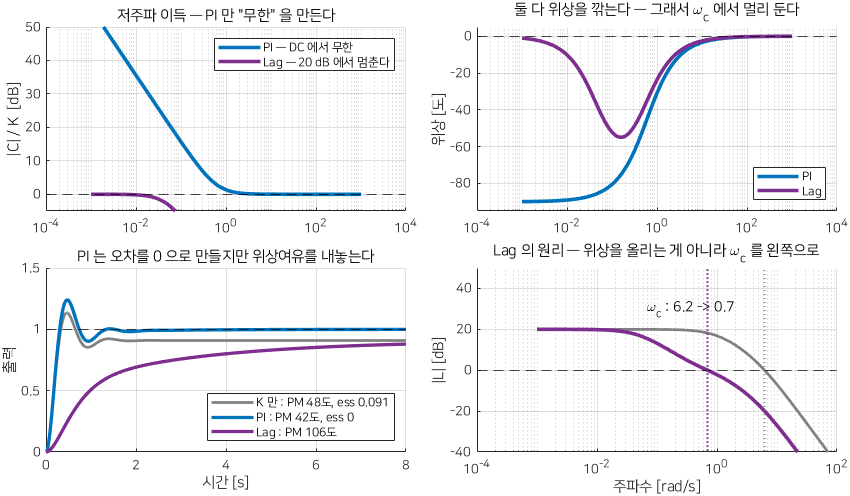

PI 와 Lag — 저주파를 무한히 올리는가 유한하게 올리는가

**그림 파일** `w11b_pi_vs_lag.png` — `make_figures.m` 의 `fig_w11b_pi_vs_lag` · 다시 만들려면 `make_figures('w11b_pi_vs_lag')`

그림 해석

왜 중요한가 — 둘의 선택 기준은 하나뿐입니다. **오차가 정확히 **$0$** 이어야 하면 PI, **$1\%$** 면 충분하면 Lag.** 적분 포화가 걱정되면 Lag 를 고릅니다.

## 6-3. 네 제어기를 한 표로

여기까지가 오늘의 연장통입니다. 한 표에 모읍니다.

외우는 법 두 줄입니다.

- **오른쪽(고주파)을 올리는 것이 위상을 올린다** — PD, Lead

- **왼쪽(저주파)을 올리는 것이 오차를 줄인다** — PI, Lag

그리고 **PD 와 PI 는 끝없이 올라가고, Lead 와 Lag 는 멈춥니다.** 멈추는 쪽이 실물에서 쓰는 것입니다.

7주차와의 연결 — 7주차에서 근궤적으로 PD 를 설계했습니다. 같은 제어기를 이번에는 보드 선도에서 설계했습니다. 두 평면의 대응입니다.

**같은 **$\phi$** 라는 글자가 두 평면에서 각각 다른 뜻으로 쓰이는 것**에 주의하십시오. 근궤적에서는 목표 극점에서 본 각도이고, 보드에서는 위상여유의 부족분입니다.

## 7. 앱에서 손으로 끌어 보기

왜 필요한가 — 지금까지는 숫자를 먼저 계산하고 코드로 확인했습니다. 실무와 시험에서는 **앱에서 끌면서** 합니다. 끌었을 때 무엇이 어떻게 변하는지 미리 알아 두면 훨씬 빠릅니다.

이 절의 내용은 `W11B_04_app_hands_on.m` 에서 전부 숫자로 확인할 수 있습니다. **앱을 열어 직접 끌어 보면서** 이 절을 읽으십시오.

>> G = tf(1, [1 1 0]);  controlSystemDesigner(G)

## 7-1. $K$ 는 위상을 바꾸지 않는다

왜 중요한가 — 앱에서 가장 많이 하는 조작이 이득 드래그입니다. 그런데 위상 곡선은 **아무리 끌어도 움직이지 않습니다.** 처음 보면 고장난 줄 압니다.

유도 — $C = K$ 이면 $L = KG$ 이고 $K$ 가 실수 양수이므로


$$\angle L(j\omega) = \angle K + \angle G(j\omega) = 0 + \angle G(j\omega)$$


즉 위상은 플랜트가 전부 정합니다. $K$ 는 **크기만** 올립니다.

그러면 왜 PM 이 바뀌는가 — 위상 곡선은 그대로지만 **그 곡선을 읽는 자리가 바뀌기 때문**입니다. $K$ 를 올리면 $0$ dB 교차점이 오른쪽으로 가고, 거기서 위상을 다시 읽습니다.

Kv7 = [25; 100; 400];
n7 = numel(Kv7);
wc7 = zeros(n7,1); ph7 = zeros(n7,1); pm7 = zeros(n7,1);
for k = 1:n7
    [~, p_, ~, w_] = margin(Kv7(k)*G1);
    wc7(k) = w_; pm7(k) = p_;
    ph7(k) = angle(evalfr(G1, 1i*w_))*180/pi;        % 플랜트만의 위상
end
table(Kv7, wc7, ph7, 180 + ph7, pm7, ...
    'VariableNames', {'K', 'wc', 'G의_위상_deg', '180_더하기', 'PM_deg'})

읽는 법 — 셋째 열이 **플랜트 **$G$** 하나만의 위상**입니다. $K$ 가 들어가지 않았는데도 PM(다섯째 열)과 넷째 열이 완전히 같습니다. 즉 **PM 은 플랜트의 위상 곡선 위의 한 점을 읽은 것**뿐입니다.

앱에서 끌어 보기 — 크기 곡선을 위아래로 끌면서 아래쪽 위상 곡선을 보십시오. 꼼짝도 하지 않습니다. 움직이는 것은 **위상 곡선 위의 표시점**입니다.

## 7-2. 동그라미를 왼쪽으로 끌면 PM 이 올라간다

왜 그런가 — 영점을 왼쪽으로 옮기면 그 영점의 위상 기여가 **더 일찍** 올라옵니다. $\arctan(\omega/z)$ 에서 $z$ 가 작아지면 같은 $\omega$ 에서 각이 커집니다.

4-4절의 Lead 제어기 $C = 754.86(s+z)/(s+45.88)$ 에서 영점 $z$ 만 끌어 봅니다.

zv = [20; 10; 6; 3; 1.5];
n8 = numel(zv);
pm8 = zeros(n8,1); wc8 = zeros(n8,1); os8 = zeros(n8,1); dc8 = zeros(n8,1);
for k = 1:n8
    Ck = 754.86*(s + zv(k))/(s + 45.88);
    Lk = Ck*G1;
    [~, p_, ~, w_] = margin(Lk);
    pm8(k) = p_; wc8(k) = w_;
    os8(k) = stepinfo(feedback(Lk,1)).Overshoot;
    dc8(k) = dcgain(s*Lk);                        % Kv
end
table(zv, pm8, wc8, os8, dc8, 1./dc8, ...
    'VariableNames', {'영점위치', 'PM_deg', 'wc', 'OS_퍼센트', 'Kv', '램프오차'})

읽는 법 — 영점을 $20$ 에서 $1.5$ 까지 왼쪽으로 끌면

- PM 이 $24.5^\circ \to 69.4^\circ$ 로 **계속 올라간다**

- 오버슈트가 $57.6\% \to 3.5\%$ 로 계속 줄어든다

- 교차주파수는 $20.8 \to 15.6$ 으로 조금 내려간다

- **그런데 **$K_v$** 가 **$329 \to 24.7$** 로 떨어진다** — 램프오차가 $0.003 \to 0.041$

마지막 줄이 함정입니다. 영점을 왼쪽으로 너무 많이 끌면 **저주파 이득이 깎여 정상상태오차 사양이 깨집니다.** $K_v = \lim s L$ 안에 영점 위치가 들어가기 때문입니다 ($K/\alpha \cdot z/p$ 꼴).

그래서 앱에서 끌 때는 **계단응답 창만 보지 말고 램프오차도 같이 봐야 합니다.** 7-4절의 "요구사항 그리기" 가 그래서 필요합니다.

극점은 반대입니다 — 극점($\times$)을 **오른쪽**으로 끌면 Lead 가 더 넓은 주파수대를 덮어 위상을 더 주지만, 고주파 이득 $K/\alpha$ 가 커집니다. 3-3절의 문제가 커지는 것입니다.

## 7-3. 영점과 극점의 순서를 바꾸면 Lead $\leftrightarrow$ Lag

왜 알아야 하나 — 앱에서 끌다가 **영점이 극점을 지나쳐 버리는 일**이 자주 생깁니다. 그 순간 제어기의 성질이 완전히 뒤집힙니다. 그런데 화면의 모양은 비슷해 보여서 눈치채지 못합니다.

pr = {'영점 6.08 · 극점 45.9  (Lead)'; '영점 45.9 · 극점 6.08  (Lag)'};
zz = [6.078; 45.88]; pp = [45.88; 6.078];
ph9 = zeros(2,1); dc9 = zeros(2,1); hf9 = zeros(2,1);
wsc2 = logspace(-1, 3, 4001);
for k = 1:2
    Ck = (s + zz(k))/(s + pp(k));
    fr = squeeze(angle(freqresp(Ck, wsc2)))*180/pi;
    if k == 1, ph9(k) = max(fr); else, ph9(k) = min(fr); end
    dc9(k) = dcgain(Ck);
    hf9(k) = abs(evalfr(Ck, 1e5i));
end
table(pr, ph9, dc9, hf9, dc9./hf9, ...
    'VariableNames', {'배치', '위상_극값_deg', 'DC이득', '고주파이득', '비율_alpha'})

읽는 법 — 같은 두 숫자를 자리만 바꿨는데

- Lead : 위상이 $+50^\circ$ 까지 올라간다. DC 이득이 $0.132$ (작다)

- Lag : 위상이 $-50^\circ$ 까지 내려간다. DC 이득이 $7.55$ (크다)

비율 열이 $\alpha$ 와 $1/\alpha$ 로 정확히 뒤집힌 것을 확인하십시오.

앱에서 알아보는 법 — **위상 곡선의 봉우리가 위로 솟았으면 Lead, 아래로 꺼졌으면 Lag** 입니다. 끌면서 이 모양만 보면 됩니다. 숫자를 읽을 필요 없습니다.

## 7-4. 요구사항을 그려 놓고 끈다 · 세션을 저장해 비교한다

왜 필요한가 — 7-2절에서 보았듯이 한 사양을 좋게 하면 다른 사양이 나빠집니다. 끌면서 **여러 사양을 동시에** 봐야 합니다. 그 방법이 두 가지 있습니다.

**(1) 설계 요구사항 그리기** (Design Requirements)

그려 놓으면 **합격 구역이 색으로 칠해집니다.** 끌면서 곡선이 색칠한 구역을 건드리는지만 보면 됩니다. 11A주차 4절에서 사양을 주파수축의 띠로 번역한 것이 여기서 화면에 그려지는 것입니다.

**(2) 세션 저장과 비교** (Store / Compare)

- 마음에 드는 설계가 나오면 **Store** 를 눌러 이름을 붙여 둔다

- 다른 설계를 해 보고 **Compare** 로 두 설계의 곡선을 겹쳐 본다

- 설계를 망쳤으면 저장해 둔 것으로 돌아간다

교수님 수업에서 쓴 방법이 이것입니다. $K$ 만 쓴 것, Lead 를 넣은 것, Lead 를 두 단 넣은 것을 각각 저장해 두고 마지막에 겹쳐서 비교합니다.

**(3) 폐루프와 제어입력 창 띄우기**

앱의 기본 화면에는 개루프 보드와 폐루프 계단응답만 있습니다. 두 개를 더 띄워야 합니다.

나이퀴스트 창은 그냥 열면 비어 있습니다. 창의 설정에서 보여 줄 대상으로 **Open loop **$L$ 을 골라 줘야 합니다. 10주차에서 쓴 그 선도입니다.

## 8. 종합 설계 — 모터 위치제어를 다섯 단계로

이제 처음부터 끝까지 한 번 해 봅니다. 5주차부터 쓴 학기 플랜트, **DC 모터의 위치제어**입니다.

G_m = plant_dcmotor('position');
G_m

극점이 $0$, 그리고 전기·기계 시정수에서 오는 두 개입니다. 적분기가 하나 있으므로 **형 1** 입니다.

table(pole(G_m), 'VariableNames', {'극점'})

이 설계가 지금까지와 다른 점이 두 가지 있습니다.

- **제어입력이 모터에 걸리기까지 **$0.02$** 초 늦는다** — 앱은 이것을 못 다룹니다 (8-5절)

- **모터 전압이 **$12$** V 로 제한된다** — 앱은 이것을 안 보여 줍니다 (8-6절)

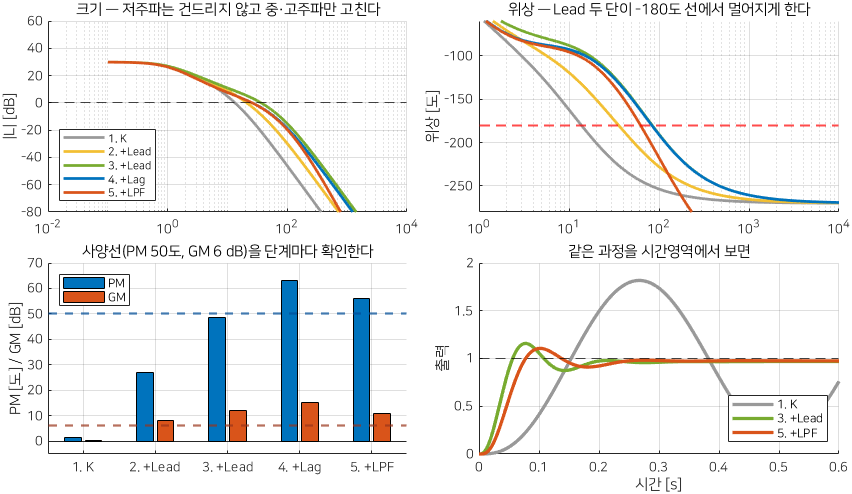

종합 설계 다섯 단계 — 사양에서 제어기까지

**그림 파일** `w11b_capstone.png` — `make_figures.m` 의 `fig_w11b_capstone` · 다시 만들려면 `make_figures('w11b_capstone')`

그림 해석

## 8-1. 1단계 — 사양을 주파수 숫자로 번역한다

사양이 이렇게 주어졌다고 합니다.

1번의 번역 — $e_{ss} = A/K_v$ 에서 $A = 0.2$, $e_{ss} \le 0.01$ 이므로


$$K_v \ge \frac{0.2}{0.01} = 20$$


2번의 번역 — 11A주차의 어림셈 $\zeta \approx PM/100$ 으로 $\zeta \ge 0.5$, 그 오버슈트는 $16\%$ 쯤입니다. 사양 3번과 함께 **안정성 여유**를 보장합니다.

## 8-2. 2단계 — $K$ 를 정한다. 그런데 불안정하다

$K_v$ 를 손으로 계산합니다. $L = K G_m$ 이므로


$$K_v = \lim_{s \to 0} s \cdot K G_m(s) = K \cdot \lim_{s \to 0} \frac{0.01 s}{0.005 s^3 + 0.06 s^2 + 0.1001 s} = K \cdot \frac{0.01}{0.1001}$$


즉 $K_v = 0.0999 K$ 입니다. $K_v \ge 20$ 이려면 $K \ge 200.2$ 입니다.

**일부러 **$K = 200$** 을 쓰겠습니다.** $200.2$ 를 보기 좋게 **내린** 것입니다. 많이들 이렇게 합니다. 이 $0.1\%$ 가 8-6절에서 어떻게 되는지 보세요.

Kv_per_K = dcgain(s*G_m);
Kpick2 = 200;
table(Kv_per_K, 20/Kv_per_K, Kpick2, Kpick2*Kv_per_K, 0.2/(Kpick2*Kv_per_K), ...
    'VariableNames', {'Kv_단위이득당', '필요한_K', '고른_K', 'Kv', '램프오차'})

그 $K$ 로 여유를 재 봅니다.

Kscan = [50; 100; 200; 400];
n9 = numel(Kscan);
pm9 = zeros(n9,1); gm9 = zeros(n9,1); wc9 = zeros(n9,1);
for k = 1:n9
    [g_, p_, ~, w_] = margin(Kscan(k)*G_m);
    gm9(k) = 20*log10(g_); pm9(k) = p_; wc9(k) = w_;
end
table(Kscan, Kscan*Kv_per_K, 0.2./(Kscan*Kv_per_K), pm9, gm9, wc9, ...
    'VariableNames', {'K', 'Kv', '램프오차', 'PM_deg', 'GM_dB', 'wc'})

읽는 법 — 사양 1번과 2·3번이 **정면으로 충돌합니다.**

- 사양 1번이 요구하는 $K = 200$ 에서는 PM 이 $-10.5^\circ$, GM 이 $-4.4$ dB 입니다. **닫으면 발산합니다**

- 여유가 괜찮은 $K = 50$ 에서는 램프오차가 $0.04$ 로 사양 1번을 어깁니다

$K$ 하나로는 불가능합니다. 위상을 올려야 합니다.

## 8-3. 3단계 — 한 단 Lead 로는 모자란다

4-2절의 다섯 단계를 그대로 따릅니다. 필요한 위상은 $50 - (-10.5) = 60.5^\circ$ 에 여유를 보태 $65^\circ$ 쯤입니다. 그런데 4-1절에서 한 단은 $55^\circ$ 를 넘기지 말라고 했습니다.

일단 해 봅니다. $\phi_{max}$ 와 $\omega_{max}$ 를 훑어 가장 좋은 결과를 찾습니다.

al_cap = (1 - sind(55))/(1 + sind(55));
best1 = [-Inf 0 0 0];
for wmx = 4:1:24
    T_ = 1/(wmx*sqrt(al_cap));
    Ck = Kpick2*(T_*s + 1)/(al_cap*T_*s + 1);
    [g_, p_, ~, w_] = margin(Ck*G_m);
    if p_ > best1(1), best1 = [p_, 20*log10(g_), w_, wmx]; end
end
table(al_cap, best1(4), best1(1), best1(2), best1(3), ...
    'VariableNames', {'alpha', 'wmax_최선', 'PM_deg', 'GM_dB', 'wc'})

읽는 법 — $\omega_{max}$ 를 $4$ 에서 $24$ 까지 어디에 놓아도 **PM 이 **$27^\circ$** 를 못 넘습니다.** 가장 좋은 자리가 $\omega_{max} = 13$ 이고 거기서 PM $26.9^\circ$, GM $11.7$ dB 입니다. GM 은 통과하는데 사양 PM $50^\circ$ 와는 거리가 멉니다.

왜 그런가 — 4-5절과 같은 이유입니다. 이 플랜트는 극점이 세 개라서 위상이 $-270^\circ$ 까지 빠르게 내려갑니다. Lead 가 크기를 올려 $\omega_c$ 를 오른쪽으로 밀면 플랜트가 그만큼 위상을 더 깎아 버립니다.

## 8-4. 4단계 — 두 단 Lead 로 합격

같은 Lead 를 두 번 겹칩니다. 그러면 위상 기여가 두 배가 됩니다 (보드 선도는 덧셈이니까).

설계값 — $\phi_{max} = 55^\circ$ 짜리를 두 개, 둘 다 $\omega_{max} = 22$ rad/s 에 놓습니다. 두 단을 **같은 자리**에 놓는 것은 설계를 단순하게 하려는 선택입니다. 4-5절처럼 떨어뜨려 놓으면 더 넓은 대역을 덮습니다.

w_cap = 22;
T_cap = 1/(w_cap*sqrt(al_cap));
C1_cap = (T_cap*s + 1)/(al_cap*T_cap*s + 1);
C_cap = minreal(Kpick2*C1_cap*C1_cap);
table(al_cap, T_cap, 1/T_cap, 1/(al_cap*T_cap), -10*log10(al_cap), ...
    Kpick2/al_cap^2, ...
    'VariableNames', {'alpha', 'T', '영점', '극점', '한단_올림_dB', 'C_고주파이득'})

영점 두 개가 $6.94$, 극점 두 개가 $69.8$ 입니다. 여유를 잽니다.

[g_cap, p_cap, ~, wc_cap] = margin(C_cap*G_m);
T_cl = feedback(C_cap*G_m, 1);
s_cl = stepinfo(T_cl);
table(p_cap, 20*log10(g_cap), wc_cap, bandwidth(T_cl), s_cl.Overshoot, s_cl.SettlingTime, ...
    'VariableNames', {'PM_deg', 'GM_dB', 'wc', 'wb', 'OS_퍼센트', 'ts'})

읽는 법 — PM $60.6^\circ$, GM $24.0$ dB 입니다. **이상적인 플랜트에서는 사양 2·3번을 넉넉히 통과합니다.**

그런데 아직 두 가지를 안 봤습니다. 수송지연과 제어입력입니다. 여기서 끝냈다면 실물에서 실패합니다.

## 8-5. 5단계 — 실제 플랜트로 검증한다 : 수송지연

왜 필요한가 — 제어기가 계산한 전압이 모터에 실제로 걸리기까지 $0.02$ 초가 걸립니다. 계산하고 통신으로 보내고 구동회로가 받아 거는 데까지의 시간입니다. 이것을 **수송지연** (transport delay) 이라고 합니다.


$$u_{실제}(t) = u(t - T_d), \qquad T_d = 0.02 \text{ s}$$


라플라스 변환하면 $e^{-s T_d}$ 가 곱해집니다. 이것이 왜 문제인가 — 크기와 위상을 따로 보면 바로 보입니다.


$$|e^{-j\omega T_d}| = 1, \qquad \angle e^{-j\omega T_d} = -\omega T_d \text{ [rad]}$$


**크기는 하나도 안 바뀌고 위상만 깎입니다.** 그리고 깎이는 양이 $\omega$ 에 **비례**합니다. 고주파로 갈수록 끝없이 깎입니다.

손계산 — 8-4절에서 얻은 $\omega_c = 8.588$ rad/s 에서 깎이는 위상은


$$-\omega_c T_d = -8.588 \times 0.02 = -0.1718 \text{ rad} = -9.84^\circ$$


라디안을 도로 바꾸는 것만 조심하면 됩니다 ($\times 180/\pi$). 즉 PM $60.6^\circ$ 가 $50.7^\circ$ 쯤으로 떨어질 것으로 예상됩니다. 사양 $50^\circ$ 를 **간신히 지킵니다.**

한 가지 더 — **지연이 루프 안 어디에 있어도 여유는 똑같습니다.** 구동기 앞에 있든 센서 쪽에 있든 한 바퀴 돌아오는 길에 $e^{-sT_d}$ 가 한 번 곱해지는 것은 같기 때문입니다. 즉 루프이득 $L = CGe^{-sT_d}$ 가 같습니다. 달라지는 것은 **우리가 재는 **$y$ 입니다. 지연을 센서 쪽에 두면 제어기는 늦은 값을 보고 맞추므로 진짜 $y$ 는 지령보다 오히려 앞서 갑니다. 그래서 여기서는 지연을 **구동기 앞**(전방경로)에 두어 $y$ 가 곧 실제 출력이 되게 합니다. 9절의 Simulink 모델도 같은 자리에 둡니다.

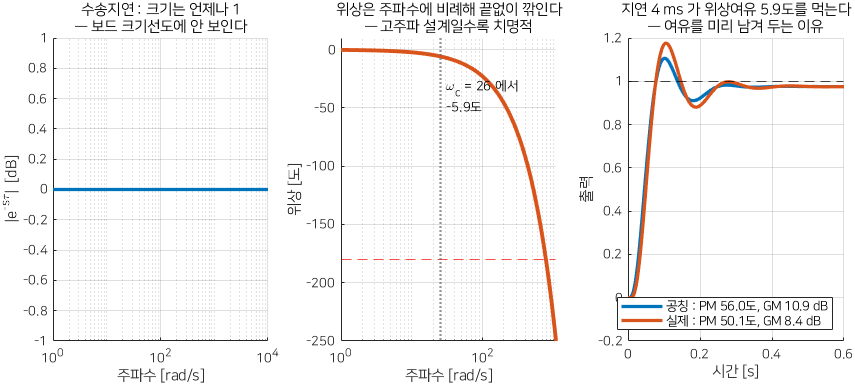

수송지연은 크기를 안 건드리고 위상만 깎는다

**그림 파일** `w11b_delay.png` — `make_figures.m` 의 `fig_w11b_delay` · 다시 만들려면 `make_figures('w11b_delay')`

그림 해석

MATLAB 검산 — 지연을 `pade` 로 유리함수로 바꿔 넣습니다. 앱은 지연을 못 받지만 `margin` 은 `pade` 근사를 쓰면 받습니다.

명령 정리 — `pade`

- **원리** — $e^{-sT_d}$ 를 같은 차수의 유리함수로 근사한다. 1차는 $\frac{1 - sT_d/2}{1 + sT_d/2}$, 차수를 올리면 더 넓은 주파수대에서 맞는다

- **입력** — `[num, den] = pade(Td, n)`. $T_d$ 는 지연 시간, $n$ 은 차수

- **출력** — 분자·분모 계수. `tf(num, den)` 으로 전달함수로 만든다

- **주의** — 분자에 **불안정 영점**(우반면)이 생깁니다. 그것이 지연의 성질을 흉내 내는 방법입니다. 차수가 낮으면 고주파에서 틀립니다. $n = 3$ 이면 $\omega T_d < 2$ 쯤까지 믿을 수 있습니다

Td_cap = 0.02;
[nd, dd] = pade(Td_cap, 3);
G_real = G_m*tf(nd, dd);
[g_r, p_r, ~, wc_r] = margin(C_cap*G_real);
T_r = feedback(C_cap*G_real, 1);
s_r = stepinfo(T_r);
nm10 = {'이상 플랜트'; '지연 0.02 s 포함'};
table(nm10, [p_cap; p_r], [20*log10(g_cap); 20*log10(g_r)], [wc_cap; wc_r], ...
    [s_cl.Overshoot; s_r.Overshoot], [s_cl.SettlingTime; s_r.SettlingTime], ...
    'VariableNames', {'플랜트', 'PM_deg', 'GM_dB', 'wc', 'OS_퍼센트', 'ts'})

읽는 법 — 예측대로입니다.

- 교차주파수가 **똑같습니다** ($8.588$). 지연이 크기를 안 건드렸으니까

- PM 이 $60.6^\circ \to 50.7^\circ$ 로 $9.84^\circ$ 떨어졌습니다. **손계산 **$-9.84^\circ$** 와 소수 둘째 자리까지 같습니다**

- GM 도 $24.0 \to 13.5$ dB 로 크게 떨어졌습니다

- 오버슈트가 $14.5\% \to 20.5\%$ 로 늘었습니다

**PM **$50.7^\circ$**, GM **$13.5$** dB — 사양 2·3번을 간신히 통과합니다.** 간신히라는 것이 중요합니다. 지연이 조금만 더 길어지면 깨집니다.

왜 중요한가 — 앱 안에서 본 $60.6^\circ$ 는 **실제 여유가 아니었습니다.** 앱은 유리함수만 다루므로 지연을 모릅니다. **지연이 있는 시스템은 반드시 Simulink 로 따로 확인해야 합니다** (9절).

## 8-6. 마지막 확인 — 제어입력

왜 필요한가 — 사양 4번이 남았습니다. 그런데 앱의 기본 화면에는 $u$ 가 없습니다. 재 봅니다.

지령에서 제어입력까지의 전달함수를 유도합니다. 1-2절 그림에서


$$u = Ce = C(r - y), \qquad y = Gu$$


둘째 식을 첫째에 넣으면 $u = C(r - Gu)$, $u$ 를 모으면 $(1 + CG)u = Cr$, 따라서


$$\frac{u}{r} = \frac{C}{1 + CG}$$


$s \to \infty$ 에서 이 값은 $C(\infty)$ 로 갑니다 ($G(\infty) = 0$ 이므로). 우리 제어기는 $C(\infty) = K/\alpha^2$ 입니다.

손계산 — $200/0.0994^2 = 20237$ 입니다. 계단 지령을 주면 첫 순간에 $20237$** V** 가 필요하다는 뜻입니다. 모터는 $12$ V 입니다.

Gu_cap = minreal(C_cap/(1 + C_cap*G_real));
t_cap = (0:1e-4:4)';
u_step = lsim(Gu_cap, ones(size(t_cap)), t_cap);
table(Kpick2/al_cap^2, max(abs(u_step)), ...
    'VariableNames', {'공식_K_over_alpha2', '실측_umax_계단'})

읽는 법 — 공식과 실측이 같습니다. **계단 지령은 이 설계로 불가능합니다.**

그런데 사양 1번은 **램프** 지령이었습니다. 램프는 첫 순간의 점프가 없으니 다릅니다. 게다가 실제 장비는 지령을 갑자기 꺾지 않고 **매끄럽게** 올립니다. 그 지령으로 다시 재 봅니다.

A_cap = 0.2; tau_cap = 0.3;
r_cap = A_cap*(t_cap - tau_cap*(1 - exp(-t_cap/tau_cap)));   % 출발이 매끄러운 램프
u_cap = lsim(Gu_cap, r_cap, t_cap);
y_cap = lsim(feedback(C_cap*G_real,1), r_cap, t_cap);
table(max(abs(u_cap)), 12, r_cap(end) - y_cap(end), 0.01, ...
    'VariableNames', {'umax_V', '한계_V', '정상상태오차', '사양'})

읽는 법 — $4.2$** V 로 한계 **$12$** V 안에 들어옵니다.** 사양 4번은 통과입니다.

그런데 정상상태오차가 $0.01001$ rad 입니다. 사양은 $0.01$ 이었습니다. $0.1\%$** 차이로 불합격입니다.** 왜 이렇게 되었는지 되짚어 봅니다.

- 8-2절에서 사양이 요구한 값은 $K \ge 200.2$ 였습니다

- 그런데 $K = 200$ 으로 **내려서** 잡았습니다. 보기 좋은 숫자라서

- 사양이 등호에 걸린 값을 줄 때는 **반드시 올려야** 합니다

고칩니다. $K$ 만 $210$ 으로 올리고 Lead 두 단은 그대로 둡니다. Lead 는 **비율**만 정하므로 $K$ 를 바꿔도 모양은 그대로입니다.

Kfix = 210;
C_fix = minreal(Kfix*C1_cap*C1_cap);
[g_f, p_f] = margin(C_fix*G_real);
Gu_fix = minreal(C_fix/(1 + C_fix*G_real));
y_fix = lsim(feedback(C_fix*G_real,1), r_cap, t_cap);
u_fix = lsim(Gu_fix, r_cap, t_cap);
table({'(1) 램프오차'; '(2) PM [deg]'; '(3) GM [dB]'; '(4) umax [V]'}, ...
    [r_cap(end) - y_cap(end); p_r; 20*log10(g_r); max(abs(u_cap))], ...
    [r_cap(end) - y_fix(end); p_f; 20*log10(g_f); max(abs(u_fix))], ...
    [0.01; 50; 6; 12], ...
    'VariableNames', {'사양', 'K_200', 'K_210', '요구값'})

읽는 법

- 램프오차 $0.01001 \to 0.009533$. **통과입니다**

- 그 대가로 PM 이 $50.73 \to 50.35$ 도, GM 이 $13.47 \to 13.04$ dB 로 조금 줄었습니다. $K$ 를 올리면 $\omega_c$ 가 오른쪽으로 가고 지연이 그만큼 더 깎기 때문입니다

- 제어전압은 $4.20 \to 4.34$ V. 여전히 한계 안입니다

**이제 네 사양 전부 통과입니다.** 다만 PM 이 $50.35$ 도로 빠듯하므로 실물에서는 다시 재야 합니다. 같은 확인을 `W11B_05_capstone.m` 7-1절에서 숫자로 다시 봅니다.

그림으로 확인합니다 ($K = 200$ 설계입니다).

tiledlayout(2, 1, 'TileSpacing', 'compact');
nexttile; hold on; grid on;
plot(t_cap, r_cap, '--', 'LineWidth', 2);
plot(t_cap, y_cap, 'LineWidth', 2.2);
xlabel('시간 [s]'); ylabel('위치 [rad]');
legend('지령 (매끄러운 램프)', '출력', 'Location', 'northwest');
title('사양 1 — 간격이 0.01 rad');
nexttile; hold on; grid on;
plot(t_cap, u_cap, 'LineWidth', 2.2);
yline(12, 'r--', 'LineWidth', 1.5); yline(-12, 'r--', 'LineWidth', 1.5);
xlabel('시간 [s]'); ylabel('제어전압 [V]'); ylim([-14 14]);
legend('u', '한계 \pm12 V', 'Location', 'northeast');
title('사양 4 — 한계 안에 들어온다');

**오늘 배운 것 중 가장 중요한 교훈입니다.** 주파수영역 설계는 $L$ 의 모양만 봅니다. 제어입력에 대해서는 **아무 말도 해 주지 않습니다.** 7주차에서 `ctrl_input` 으로 이것을 보았고, 11A주차 6절에서 센서 잡음으로 또 보았습니다. 오늘 지령의 모양으로 다시 봅니다.

고치는 길 세 가지

실무에서는 (가) 를 먼저 합니다. 지령의 모양을 정하는 것도 설계의 일부입니다.

## 9. Simulink 교차 검증 — 앱이 못 보는 두 가지

왜 필요한가 — 8절에서 두 가지를 발견했습니다. 지연과 제어입력 한계입니다. 둘 다 **앱 안에서는 볼 수 없습니다.** Simulink 에서 확인합니다.

모델은 `W11B_FreqDesign.slx` 입니다. 블록 구성입니다.

같은 표가 `.slx` 안에도 주석으로 붙어 있습니다. 원본은 한 곳 (`common/model_blocks.m`) 이고, `W11B_06_run_simulink.m` 의 1 절에서 `model_blocks(model, 'print')` 로 다시 찍어 봅니다.

신호의 순서는 이렇습니다. 8-5절에서 약속한 대로 **지연이 구동기 앞**에 있어 `y_sim` 이 곧 실제 출력입니다.

지령 $r$ → 완만화 필터 → 오차 계산 → 제어기 $C$ → 구동기 한계 → 수송지연 $e^{-sT_d}$ → 플랜트 $G$ → 출력 $y$ (그리고 $y$ 가 오차 계산으로)

블록 하나씩 — **처음 나오는 블록**만 설명합니다.

`Ramp` — 지금까지는 계단 지령만 썼습니다. 램프는 처음입니다.

- **하는 일** — 시각 `Start time` 부터 기울기 `Slope` 로 **계속 올라가는** 신호를 만든다. 수식으로는 $r(t) = A t$, 라플라스로는 $A/s^2$

- **파라미터** — `Slope` (초당 올라가는 양 $A$), `Start time` (언제부터), `Initial output` (그 전까지 내보낼 값)

- **왜 이 블록인가** — 사양 1번이 "$0.2$ rad/s 로 돌 때 오차 $0.01$ rad 이하" 였습니다. 그 조건을 그대로 주려면 계단이 아니라 램프여야 합니다

- **주의** — 램프는 **끝없이 커집니다.** 시뮬레이션 시간을 길게 두면 출력도 그만큼 커집니다. 우리는 $4$ 초만 봅니다

`Transfer Fcn` (지령 완만화 필터) — 블록 자체는 2주차에서 썼습니다. 여기서 새로운 것은 **어디에 쓰는가** 입니다.

- 제어기 앞이 아니라 **지령 뒤, 오차 계산 앞**에 있습니다. 즉 루프 바깥입니다

- 루프 바깥이므로 $L = CGe^{-sT_d}$ 를 **건드리지 않습니다.** PM·GM·$\omega_c$ 가 하나도 변하지 않습니다

- 하는 일은 램프의 **출발만 둥글게** 만드는 것입니다. 8-6절의 그 지령이 바로 이 필터의 출력입니다


$$\frac{A}{s^2}\cdot\frac{1}{\tau s + 1} \quad \Rightarrow \quad r(t) = A\left(t - \tau\left(1 - e^{-t/\tau}\right)\right)$$


손으로 확인 — $t$ 가 커지면 $e^{-t/\tau} \to 0$ 이므로 $r \to A(t - \tau)$, 즉 **기울기는 그대로 **$A$ 이고 $\tau$ 초만큼 늦어진 램프가 됩니다. $t = 0$ 에서는 $r = 0$ 이고 $\dot{r} = 0$ 입니다. 그래서 출발이 둥글어집니다.

`Transport Delay` — 8-5절에서 식으로 다룬 그 지연입니다.

- **하는 일** — 들어온 신호를 정해진 시간만큼 늦춰 그대로 내보낸다. 전달함수로는 $e^{-sT_d}$

- **파라미터** — `Time delay` (늦추는 시간), `Initial output` (지연 동안 내보낼 값), `Buffer size` (과거 값을 저장할 개수)

- **내부적으로 어떻게 계산하는가** — 과거 입력을 버퍼에 쌓아 두고 보간해 꺼냅니다. 그래서 **가변 스텝 솔버와 궁합이 중요**합니다. 스텝이 지연보다 커지면 보간 오차가 생기므로 `MaxStep` 을 지연의 $1/10$ 이하로 둡니다

- **왜 이 블록인가** — 앱도 `margin` 도 유리함수만 다룹니다. 진짜 지연을 넣어 볼 수 있는 곳은 Simulink 뿐입니다

- **주의** — `Time delay` 를 $0$ 으로 두면 이 블록이 "직접 피드스루" 로 바뀐다는 경고가 뜹니다. 플랜트 $G$ 가 엄격 진유리이므로 실제로 대수 루프는 생기지 않습니다. 실행 스크립트에서 그 경고만 잠시 꺼 둡니다

- **대체품** — `Variable Transport Delay` (지연 시간이 변할 때), 또는 `pade` 로 만든 전달함수 (해석용)

`Saturation` — 7주차와 13주차에서 썼습니다. 여기서는 $\pm 12$ V 로 두고 **켜고 끄며** 비교합니다. 꺼 두면 앱의 결과와 정확히 같아야 하고, 켜면 8-6절의 문제가 보입니다.

실행과 대조는 `W11B_06_run_simulink.m` 이 합니다. 대조를 **세 단계로 쌓습니다.** 한 번에 다 켜면 어긋났을 때 무엇 때문인지 알 수 없기 때문입니다.

읽는 법

- 1번이 맞아야 **모델을 제대로 만들었다**는 뜻입니다. 여기서 어긋나면 계수를 잘못 넣었거나 배선이 틀렸습니다. 다음 단계를 볼 필요가 없습니다

- 2번은 8-5절의 $\mathrm{PM} = 50.7^\circ$ 를 **믿어도 되는지**를 봅니다. 진짜 지연과 3차 근사가 소수 일곱째 자리까지 겹쳤으므로 믿어도 됩니다. 지령이 완만해서 높은 주파수 성분이 적기 때문입니다

- 3번이 "$0$ 개" 라는 것이 8-6절 결론의 확인입니다. **포화가 한 번도 일하지 않았으므로 선형 설계가 그대로 성립합니다**

그리고 한 가지를 더 봅니다. 8-6절에서 지령을 완만하게 만들어 설계를 살렸는데, 그 $\tau$ 가 얼마나 중요했는지입니다.

읽는 법 — $\tau$ 를 줄이면 필요한 전압이 커지고, $\tau = 0.05$ 초부터 포화가 일을 시작합니다. 그 순간부터 $y$** 차이가 **$0$** 을 벗어납니다.** 전달함수로 예측한 응답을 더 이상 믿을 수 없다는 신호입니다.

한 가지 주의 — $\tau \to 0$ 은 **계단이 아니라 순수한 램프**입니다. 그래서 이 훑기로는 8-6절의 $20237$ V 가 나오지 않습니다. 계단은 처음부터 값이 뛰는 지령이고, 그때 필요한 전압은 제어기의 고주파 이득 $K/\alpha^2$ 그 자체입니다. 그 숫자는 `W11B_06_run_simulink.m` 의 6-1절에서 분자·분모 최고차 계수의 비로 따로 확인합니다.

## 10. 오늘의 정리 — 모양을 외운다

교수님이 수업 마지막에 한 말입니다.

**"유도는 다 잊어도 됩니다. 보드 선도의 모양 네 개만 외우십시오."**

이유는 이렇습니다. 설계는 **그림을 겹치는 일**입니다. 플랜트 곡선을 보고 "여기가 모자라네" 하고 네 모양 중 하나를 고르는 것입니다. 그 판단은 공식이 아니라 그림으로 합니다.

외울 네 모양

설계 순서 (2절)

- **1단계** $K$ — 정상상태오차. 나중에 바꾸면 다 틀어진다

- **2단계** Lead 또는 PD — 위상여유

- **3단계** Lag 또는 PI — 남은 저주파

- **4단계** 검증 — Simulink, 지연, 제어입력

틀리기 쉬운 것 둘

- 사양이 정해 준 이득은 **올려서** 잡는다. $200.2$ 를 $200$ 으로 내리면 마지막 성적표에서 불합격이 뜬다 (8-6절)

- 설계가 끝나면 **제어입력을 반드시 따로 잰다**. 보드 선도는 $u$ 에 대해 아무 말도 해 주지 않는다 (8-6절)

꼭 기억할 숫자

앱에서 꼭 할 것

- 그리드 켜고 축 고정하고 **자동 스케일 끈다** (1-1절)

- $r \to u$** 창을 띄운다** (7-4절). 안 띄우면 8-6절의 함정에 빠진다

- 설계 요구사항을 그려 놓고 끈다 (7-4절)

- 마음에 드는 설계는 **Store** 로 저장한다 (7-4절)

## 11. 다음 시간 예고

오늘은 제어기의 **모양**을 보드 선도에서 골랐습니다. 그런데 산업 현장에서 압도적으로 많이 쓰는 제어기는 이름이 따로 있습니다. **PID** 입니다.

- 오늘의 PI 와 PD 를 **합친 것**이 PID 입니다

- 그런데 그냥 합치면 안 됩니다. 미분항이 잡음을 증폭하고(3-3절), 적분항이 포화 때 쌓입니다(6절)

- 그 두 문제를 고치는 것이 다음 주의 주제입니다 — **미분 필터**와 **적분 포화 방지**(anti-windup)

- 그리고 사양 없이 **자동으로** 튜닝하는 방법도 봅니다 (`pidtune`)

숙제 안내 — `hw/W11B_HW.mlx` 에 문제가 세 개 있습니다. 1번은 몸풀기(수업 중), 2번이 기본, 3번은 선택입니다. 2번은 **오늘 배운 다섯 단계를 혼자 한 번 걸어 보는 것**입니다.